# 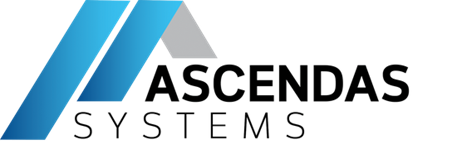

# Hand-On Model Physical System in various fidelity level 

## Introduction to Simulink

### Simulink

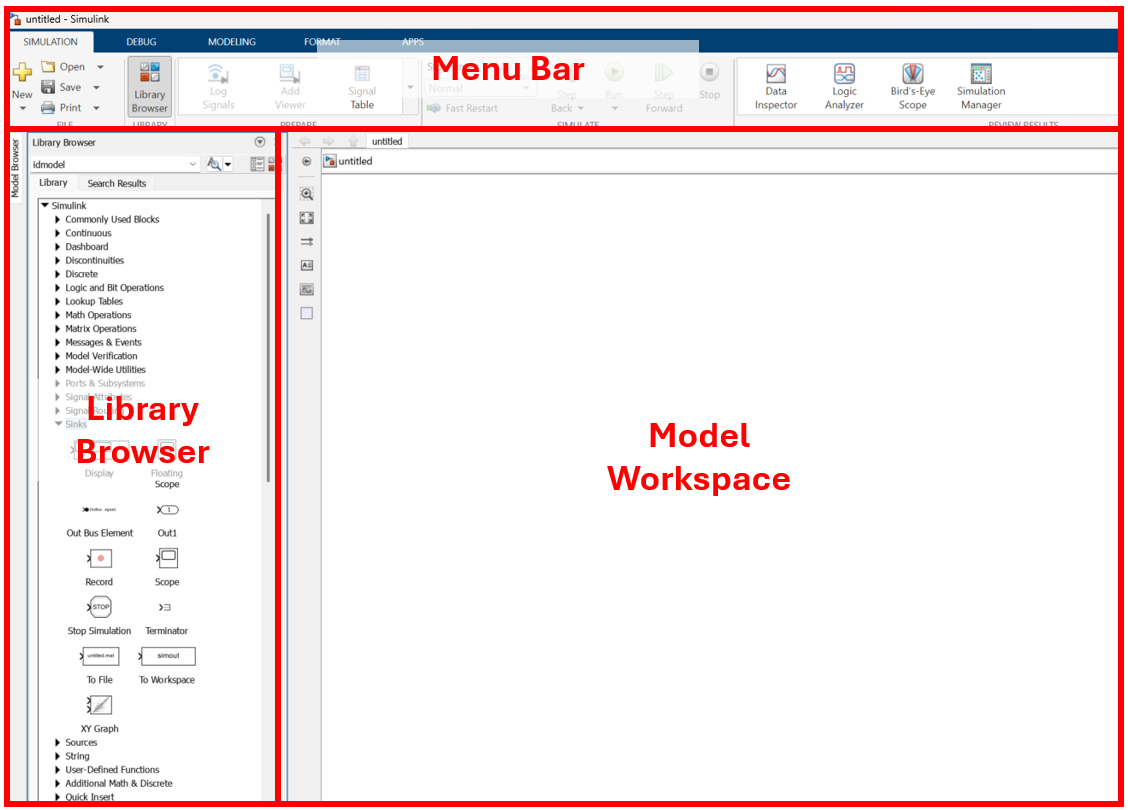

### Task 0-1: Simulink block and Simulation

- Drag and Drop "**Sine Wave**" block from "**Simulink>Sources**" to the workspace

- Drag and Drop "**Scope**" block from "**Simulink>Sink**" to the workspace

- Connect the signal from "**Sine Wave**" to "**Scope**" 

        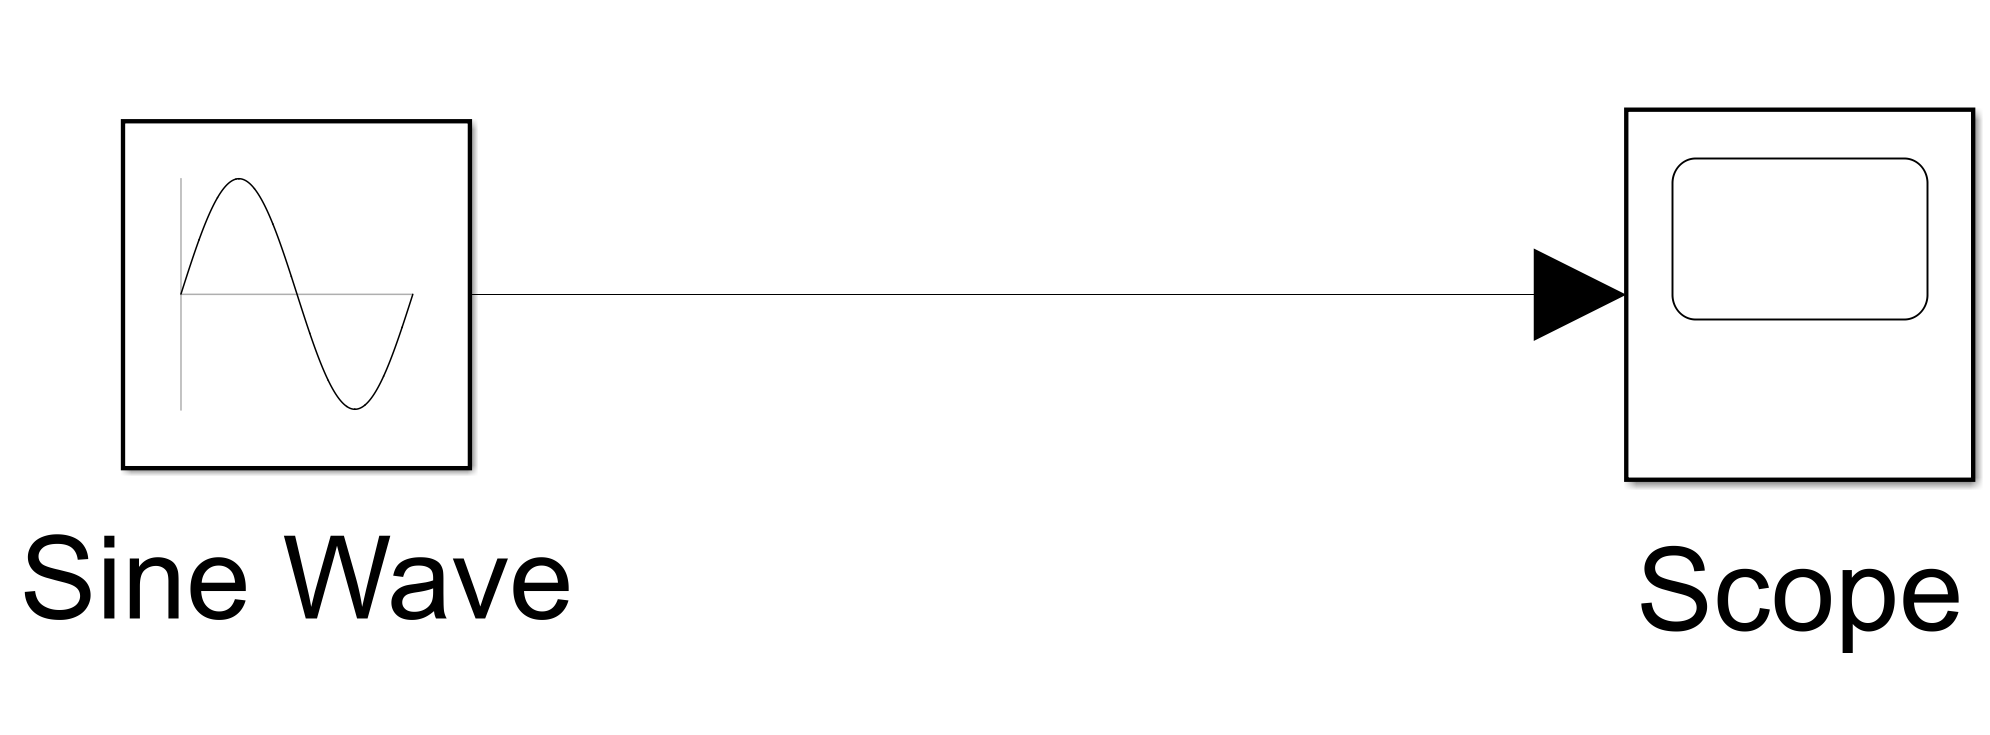

- Start simulate the system by clicking "**Run**" at Simulate section

        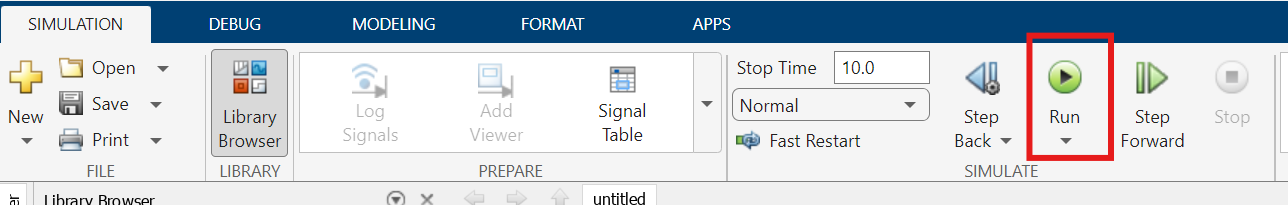

- Check the output by double click at "**Scope**"

        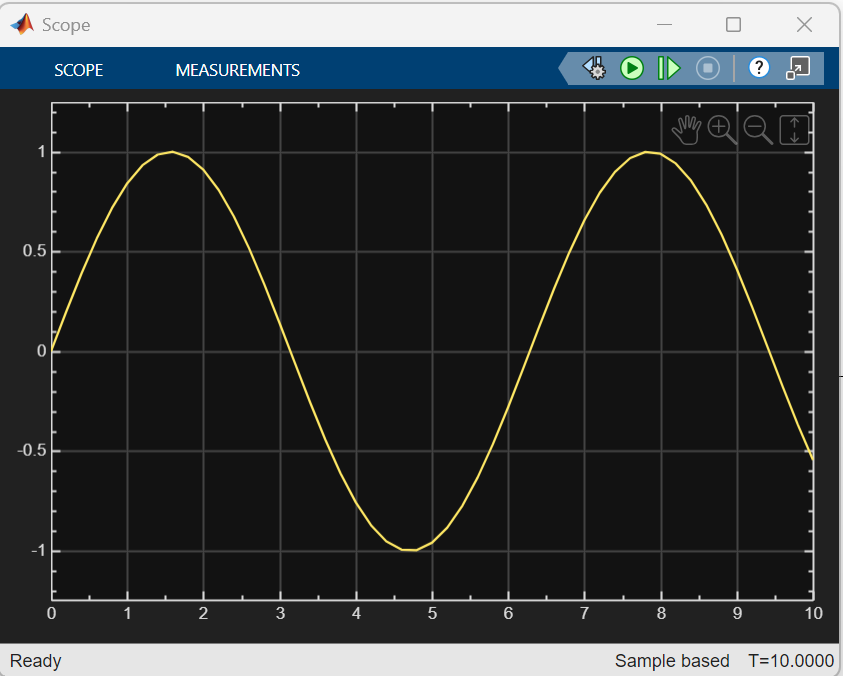

### Task 0-2: Math calculation

- Drag and Drop "**Gain**" block from "**Simulink>Math Operations**" to the workspace

- Place the "**Gain**" block in the signal line between "**Sine Wave**" and "**Scope**" block 

        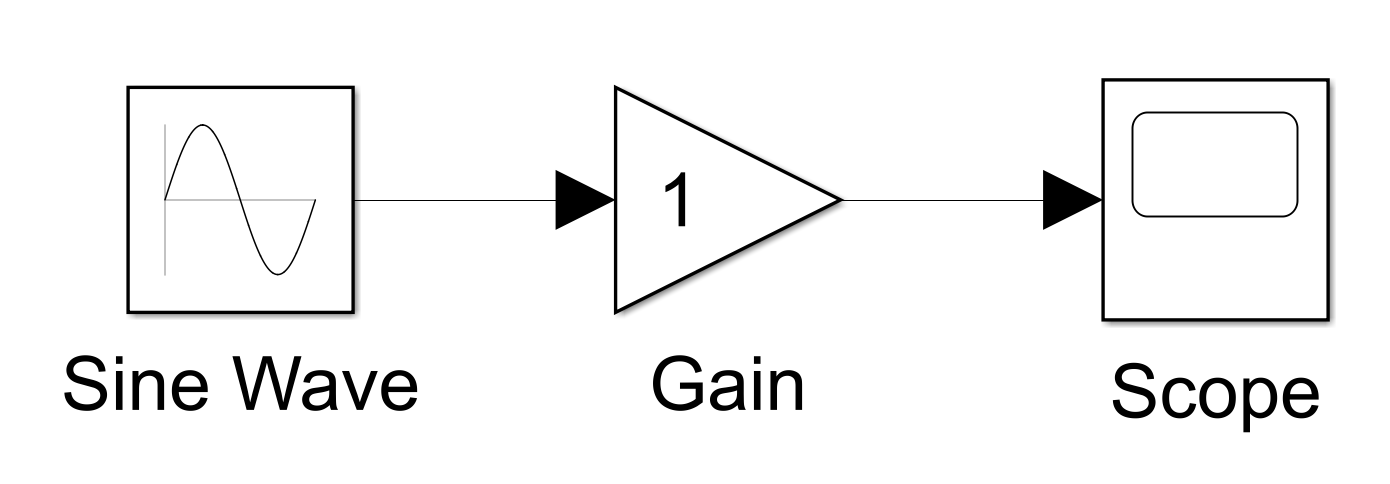

- Double click at "Gain" block and Change the gain value to 2

        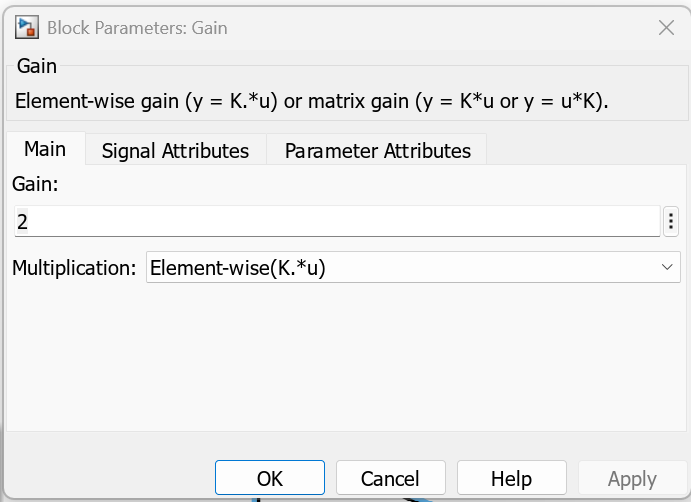

- Start simulate the system by clicking "**Run**" at Simulate section

- Check the output by double click at "**Scope**"

        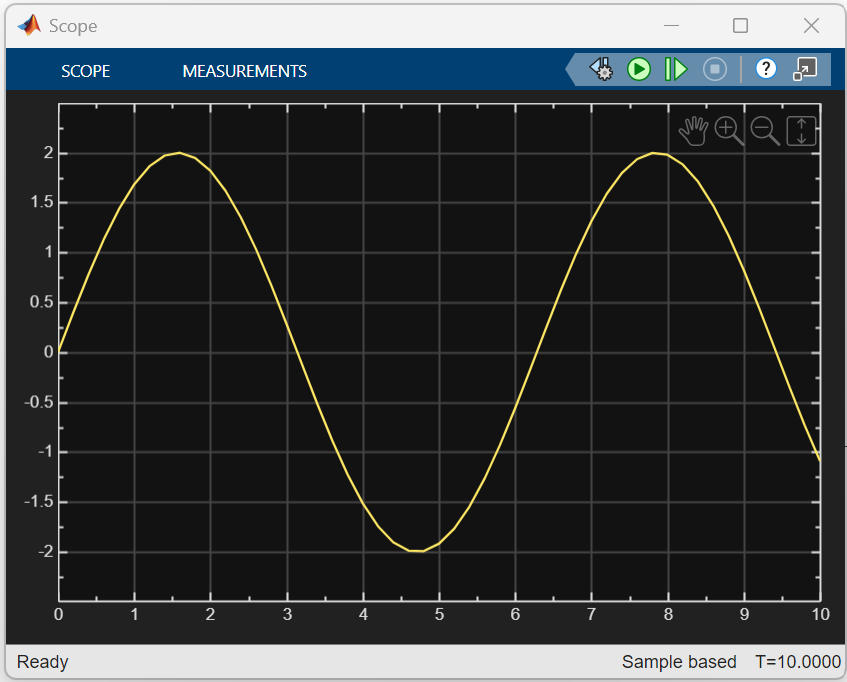

### Task 0-3: Dashboard control

- Drag and Drop "**Slider**" block from "**Simulink>Dashboard**" to the workspace

        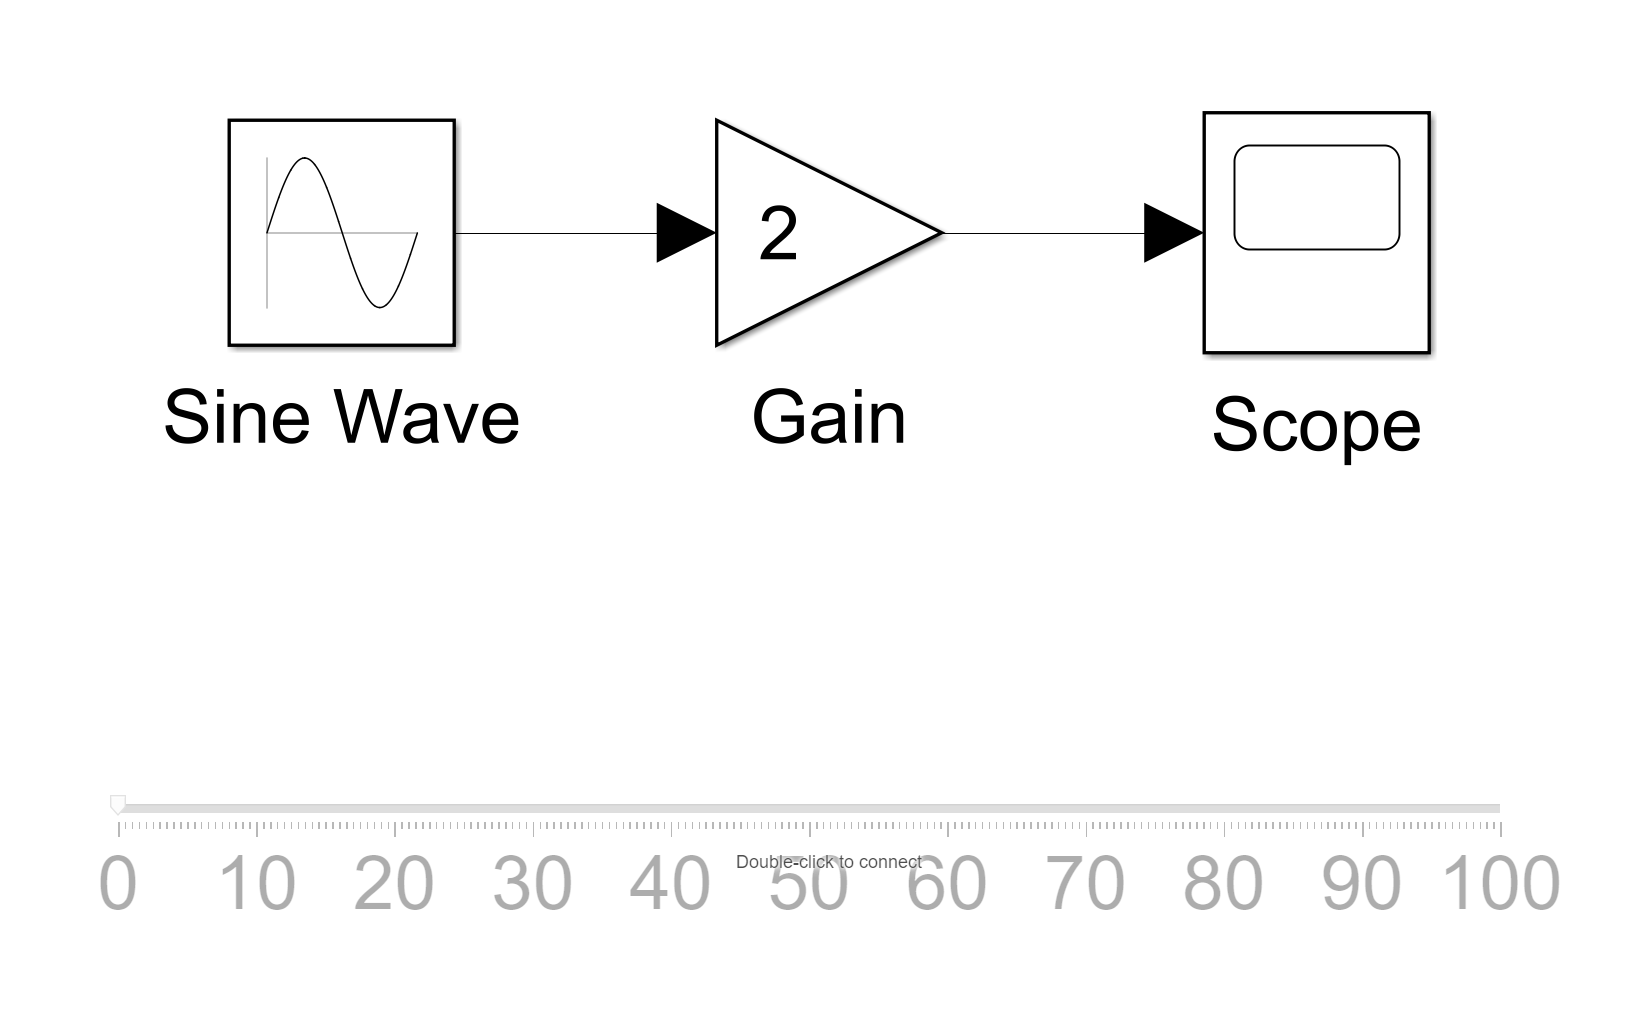 

- Double click at "**Slider**" --> Select "**Gain**" block --> Click at "**Connect**" check of the gain value --> Click "**OK**" to confirm

        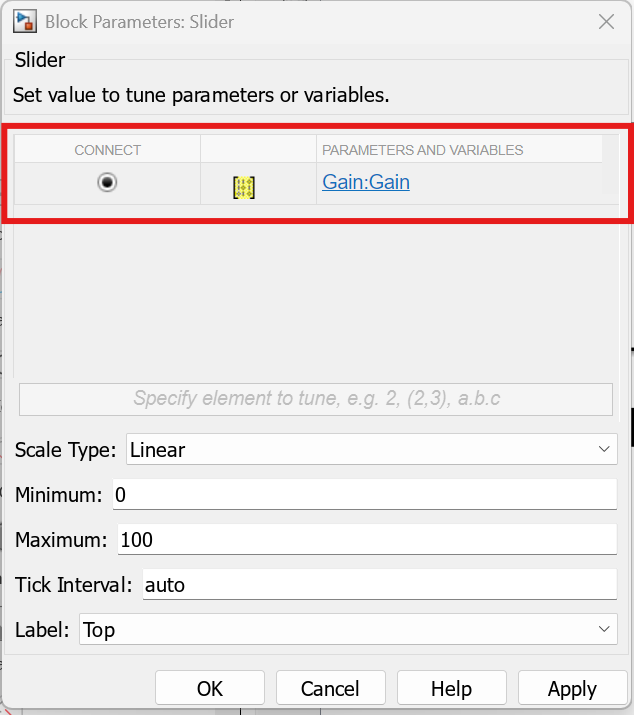

- Change "**Stop Time**" to "**Inf**"

        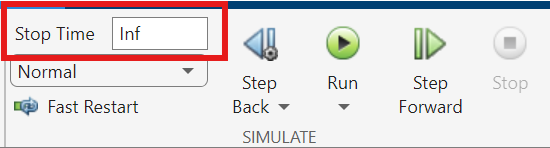

- Try to Slide the "**Slider**" bar and see the changed of Sine Wave at "**Scope**"

        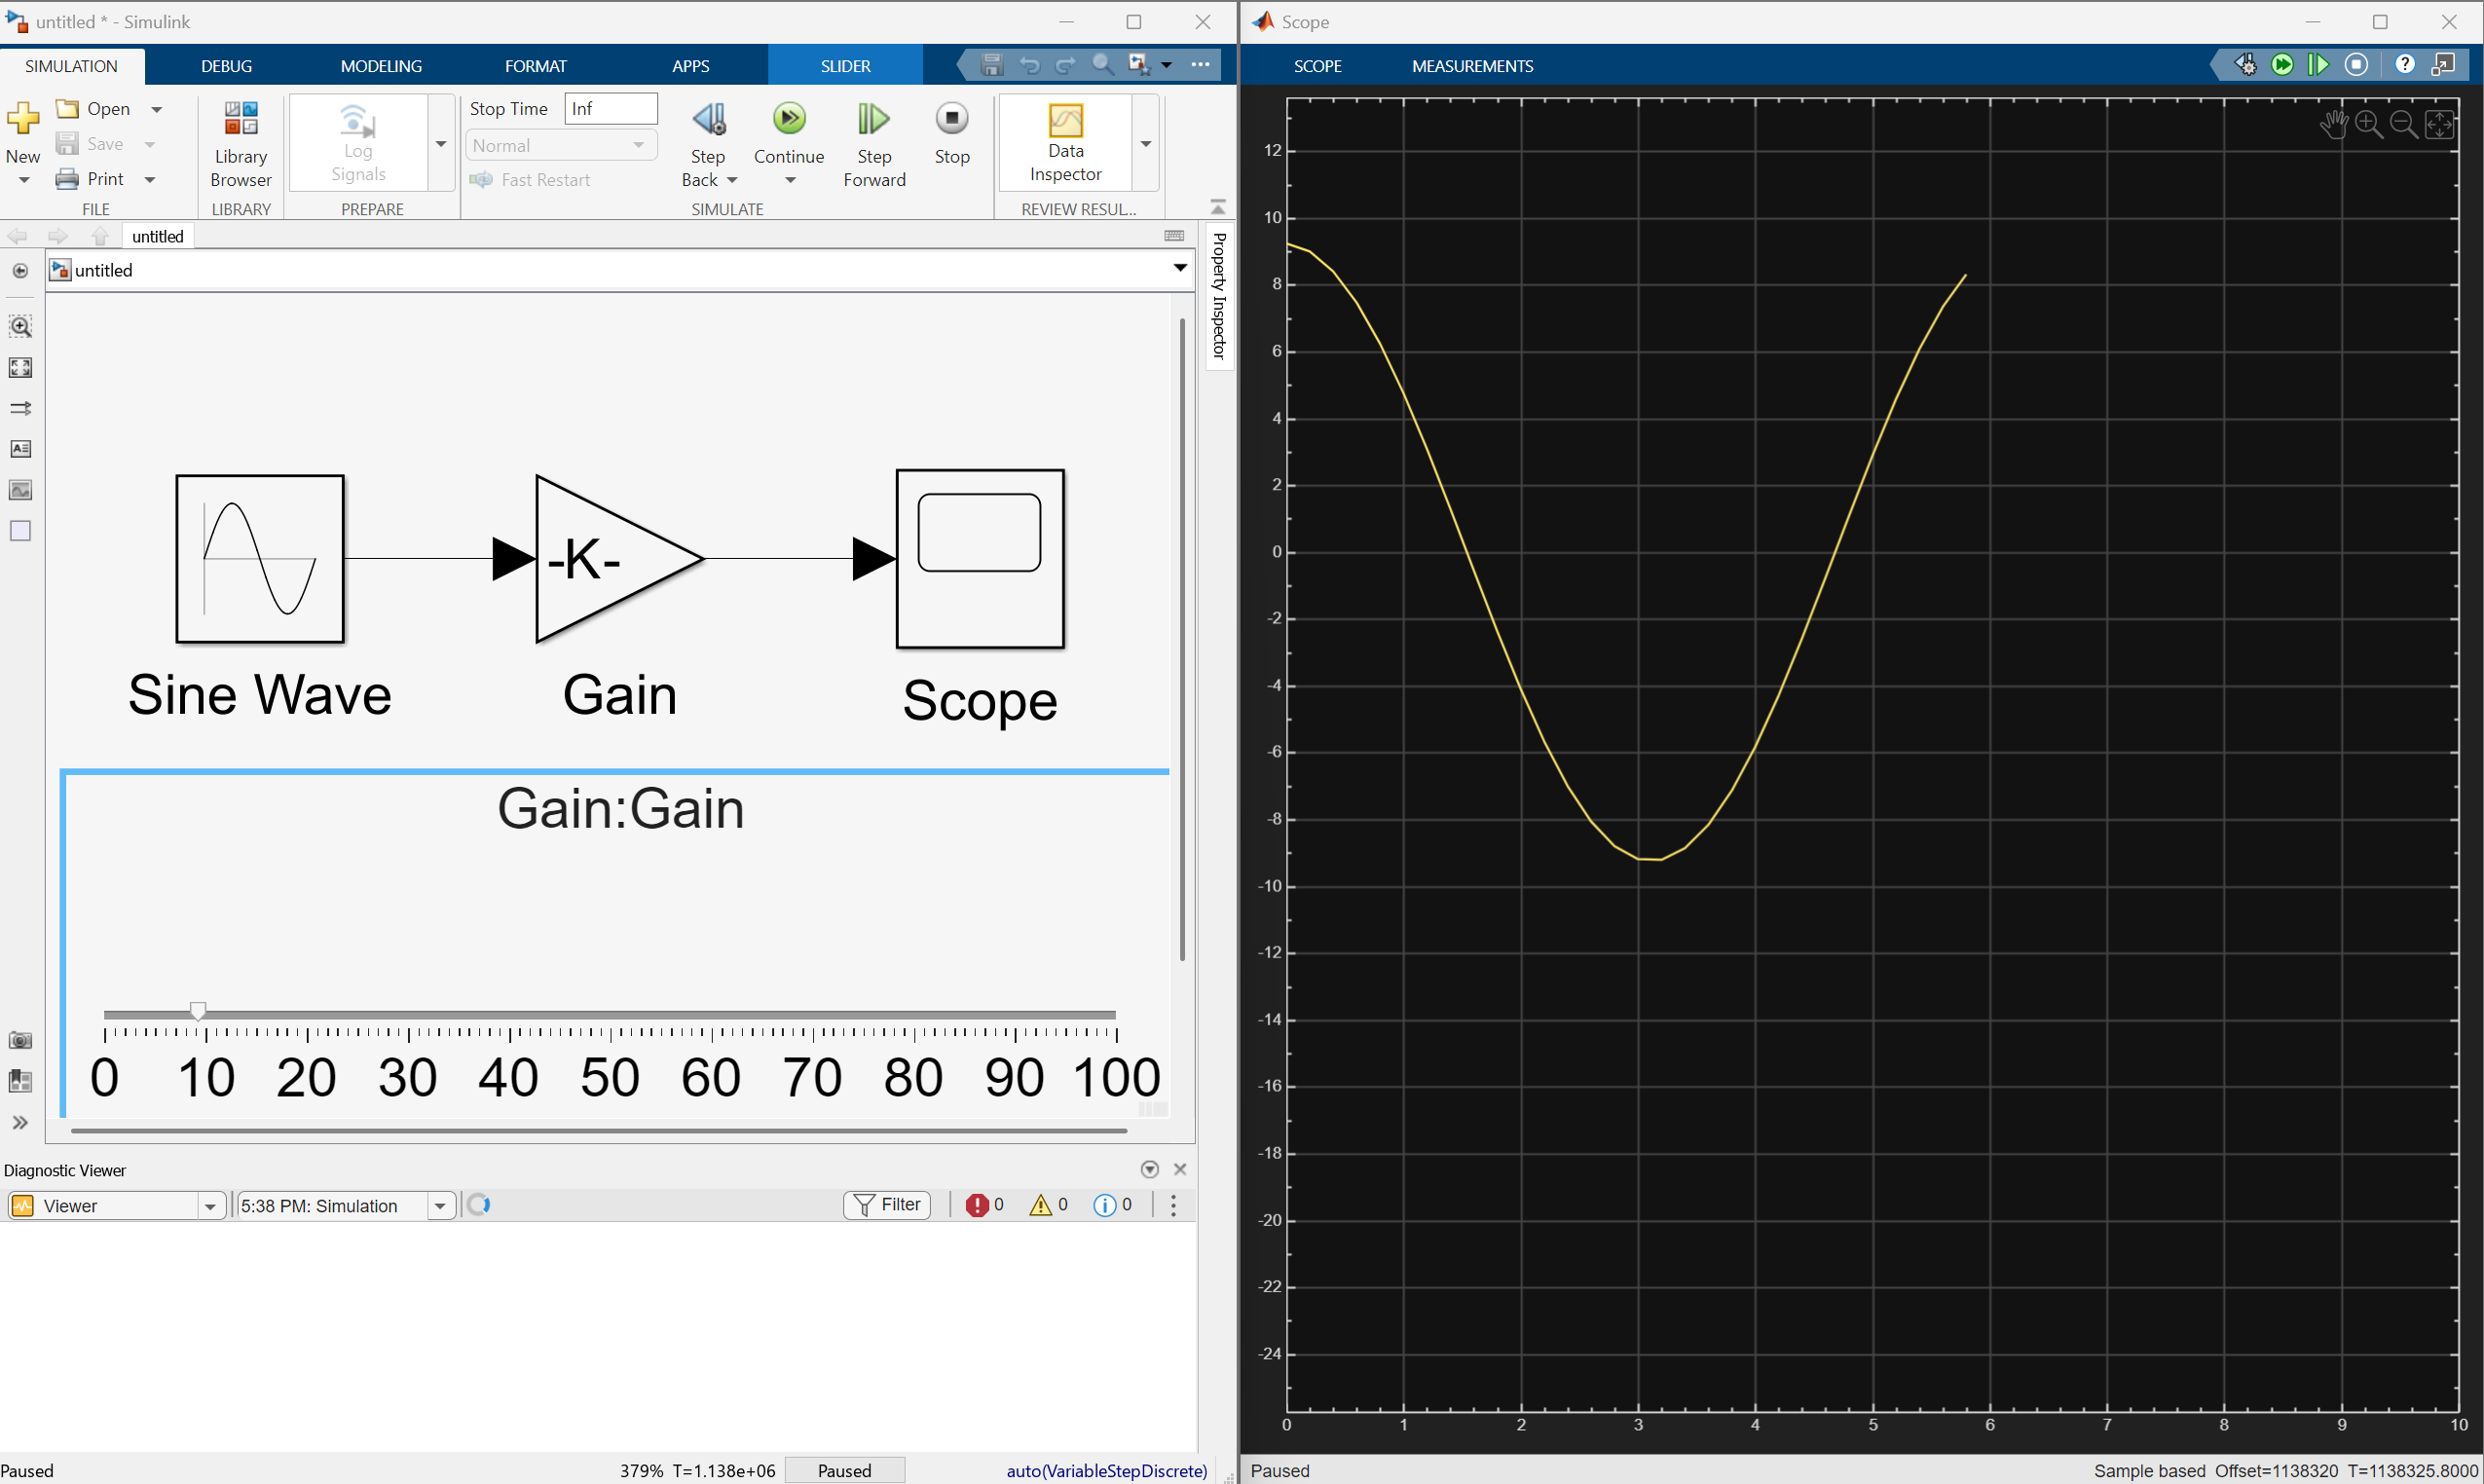

## Model Physical System in various fidelity level

### 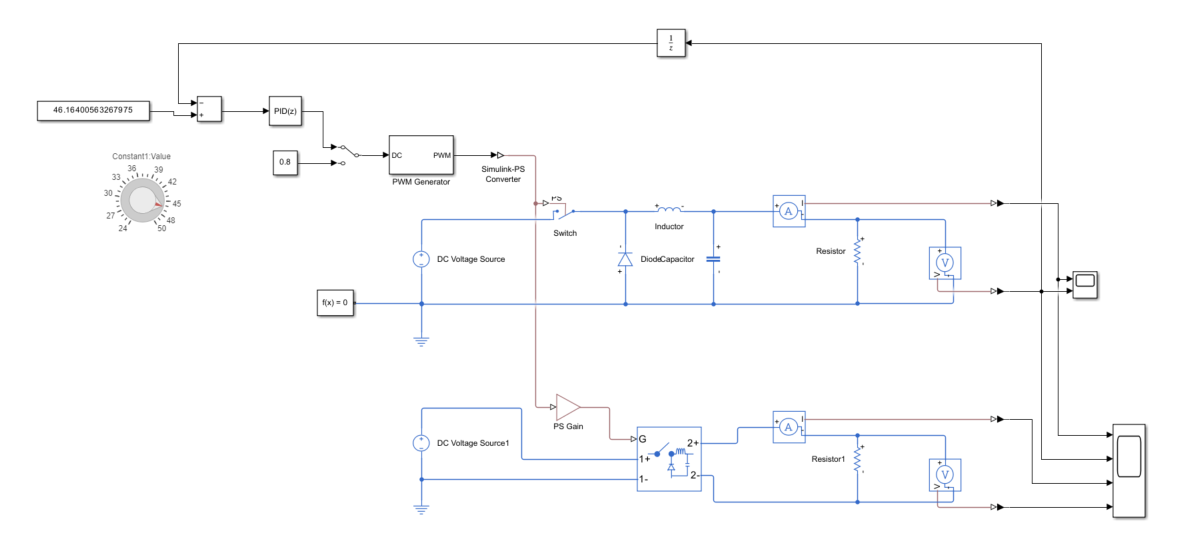

### Task 1: Create fundamental Buck converter circuit

- Drag the block from 

            **Simscape>Foundation Library>Electrical Sources**

            

            **Simscape>Foundation Library>Electrical Element**

            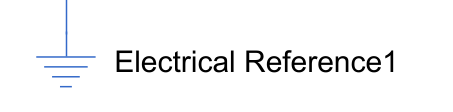

            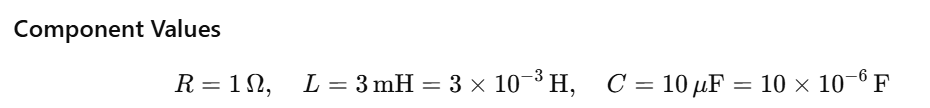

            **Simscape>Foundation Library>Electrical Sensor**

            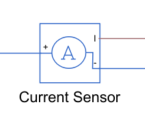

            **Simscape>Utilities**

            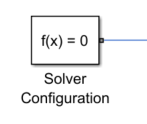

        2. Connect Buck converter circuit

        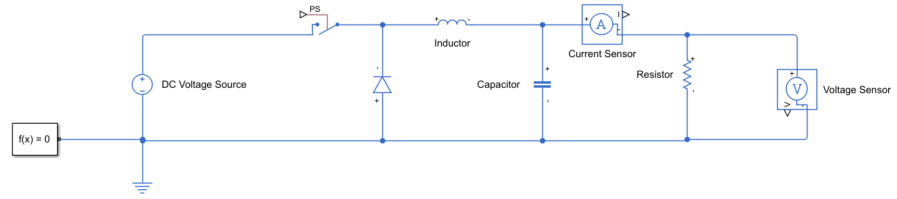

        3. Adding "PWM" to input "Switch" Block, Set up constant at 0.8 for duty cycle, Set Period to 1e-5, Sample time at 1e-6

        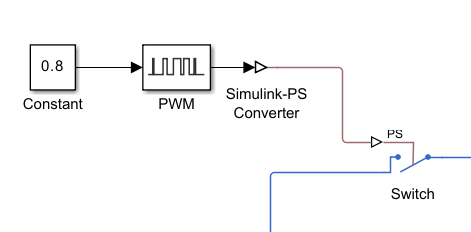

        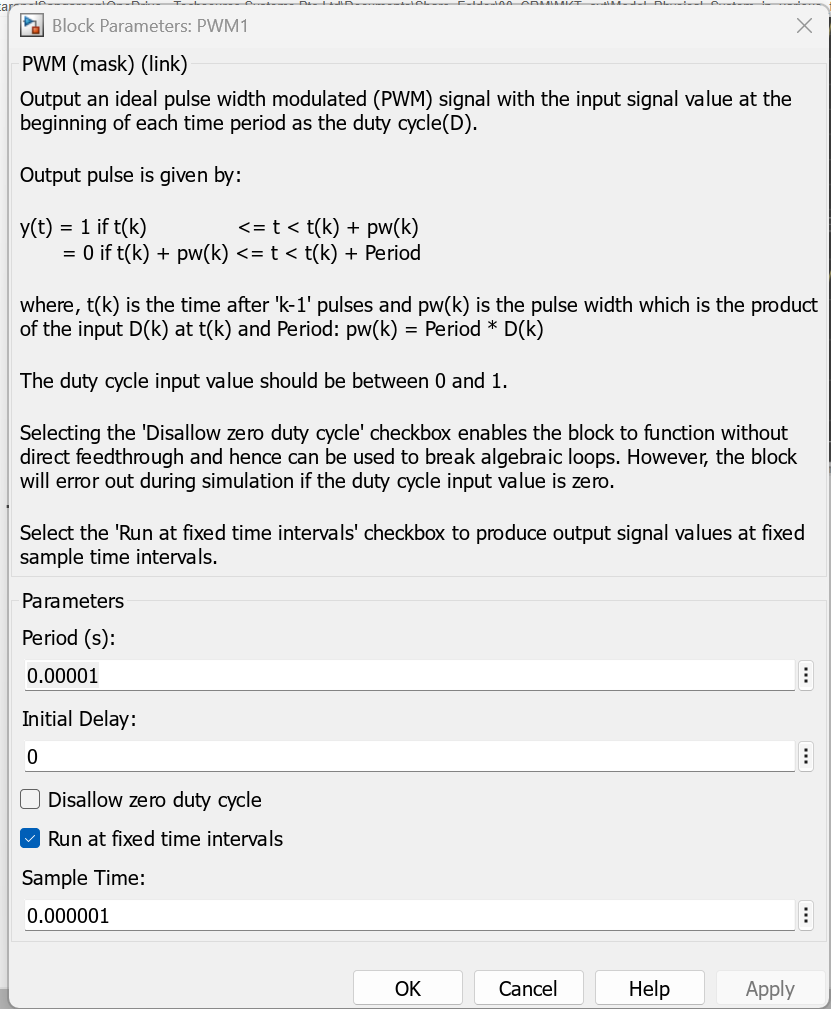

        4. Adding "Scope" Block to see the output

            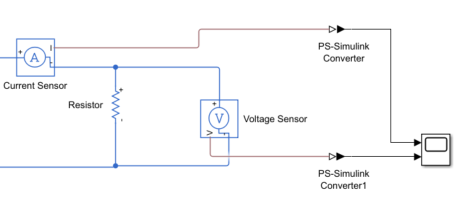

        5. Change simulation stop time to 5 second and click "Run" to start the simulation --> Check the result at "Scope" block

        *You may zoom in to scope down the time at 0 - 0.005 to see the transient response

        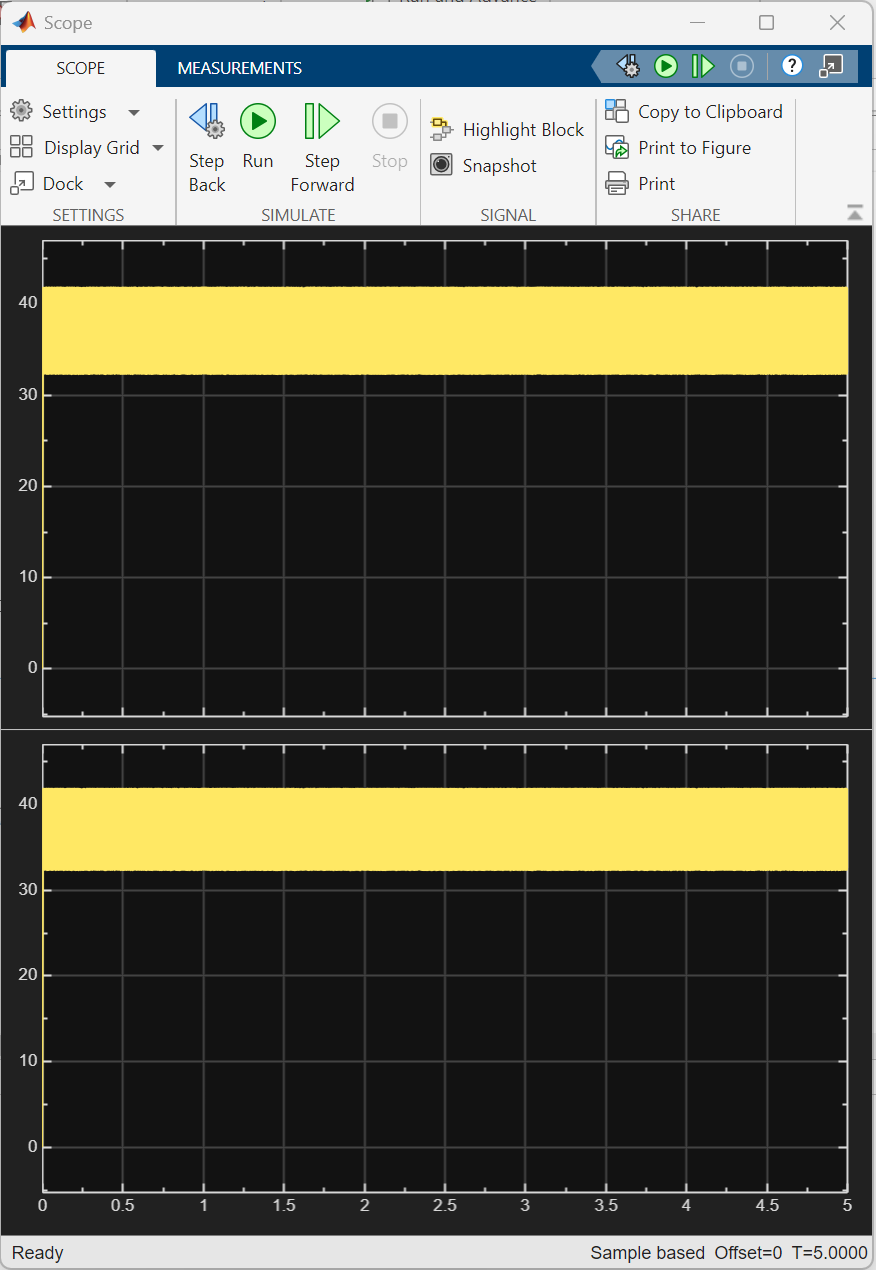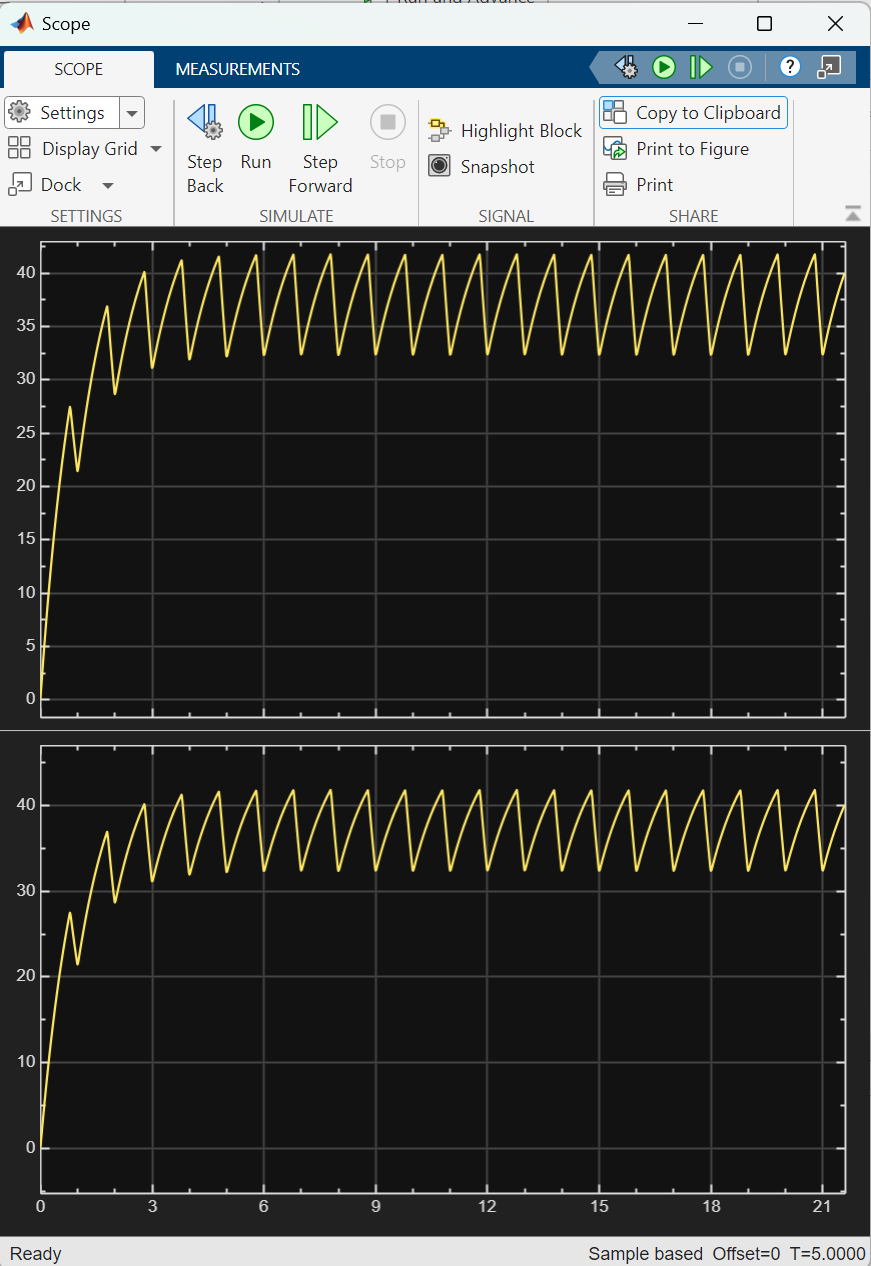

### Task 2: Create built-in Buck converter circuit from Simscape Electrical

        1. Drag the block from

        **Simscape>Electrical>Semiconductors & Converters>Buck Converter**

        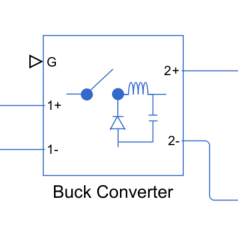

        2.  Replace the "Buck Converter" block to the previous circuit

        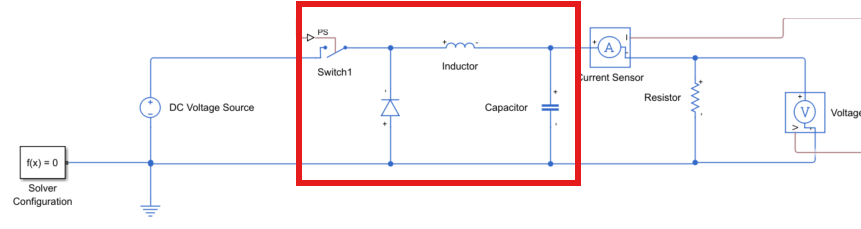

        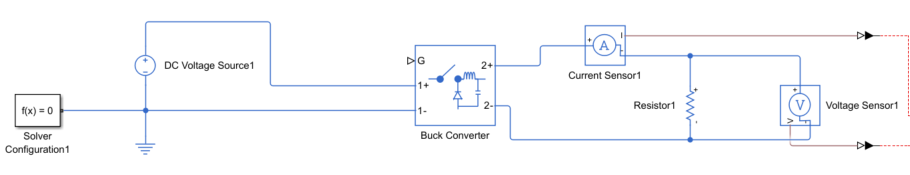

        3. Set the parameter as setting in the previous model

        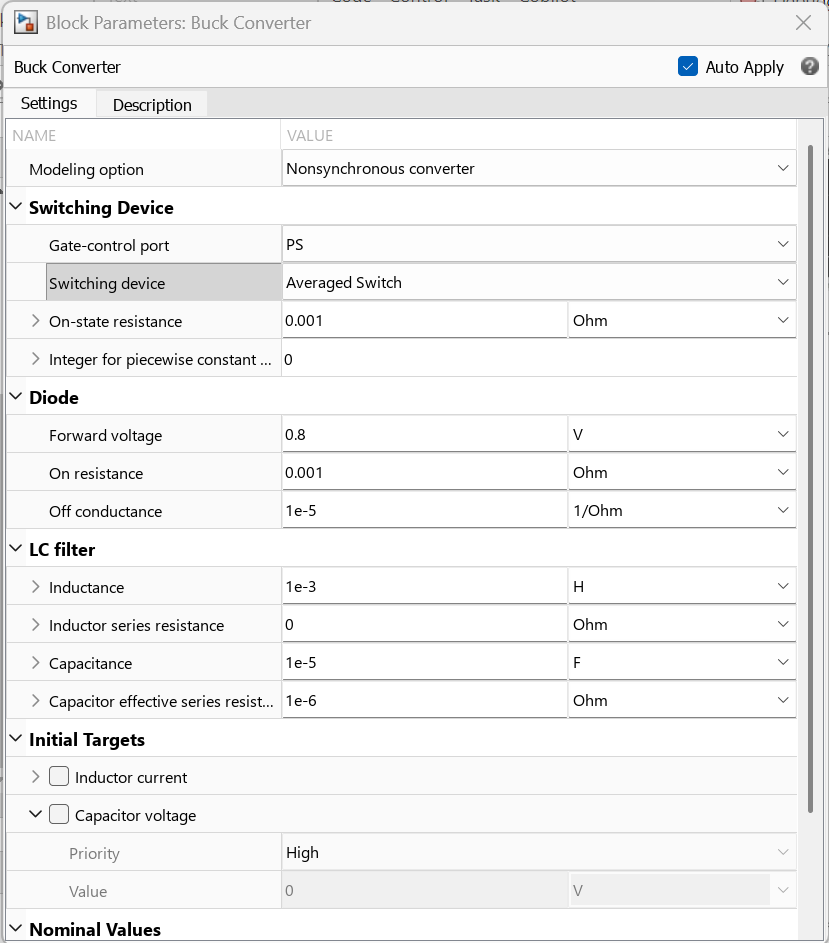

        4. Change simulation stop time to 5 second and click "Run" to start the simulation --> Check the result at "Scope" block

        *You may compare the different between 2 approch model by merge the signal to the same scope

        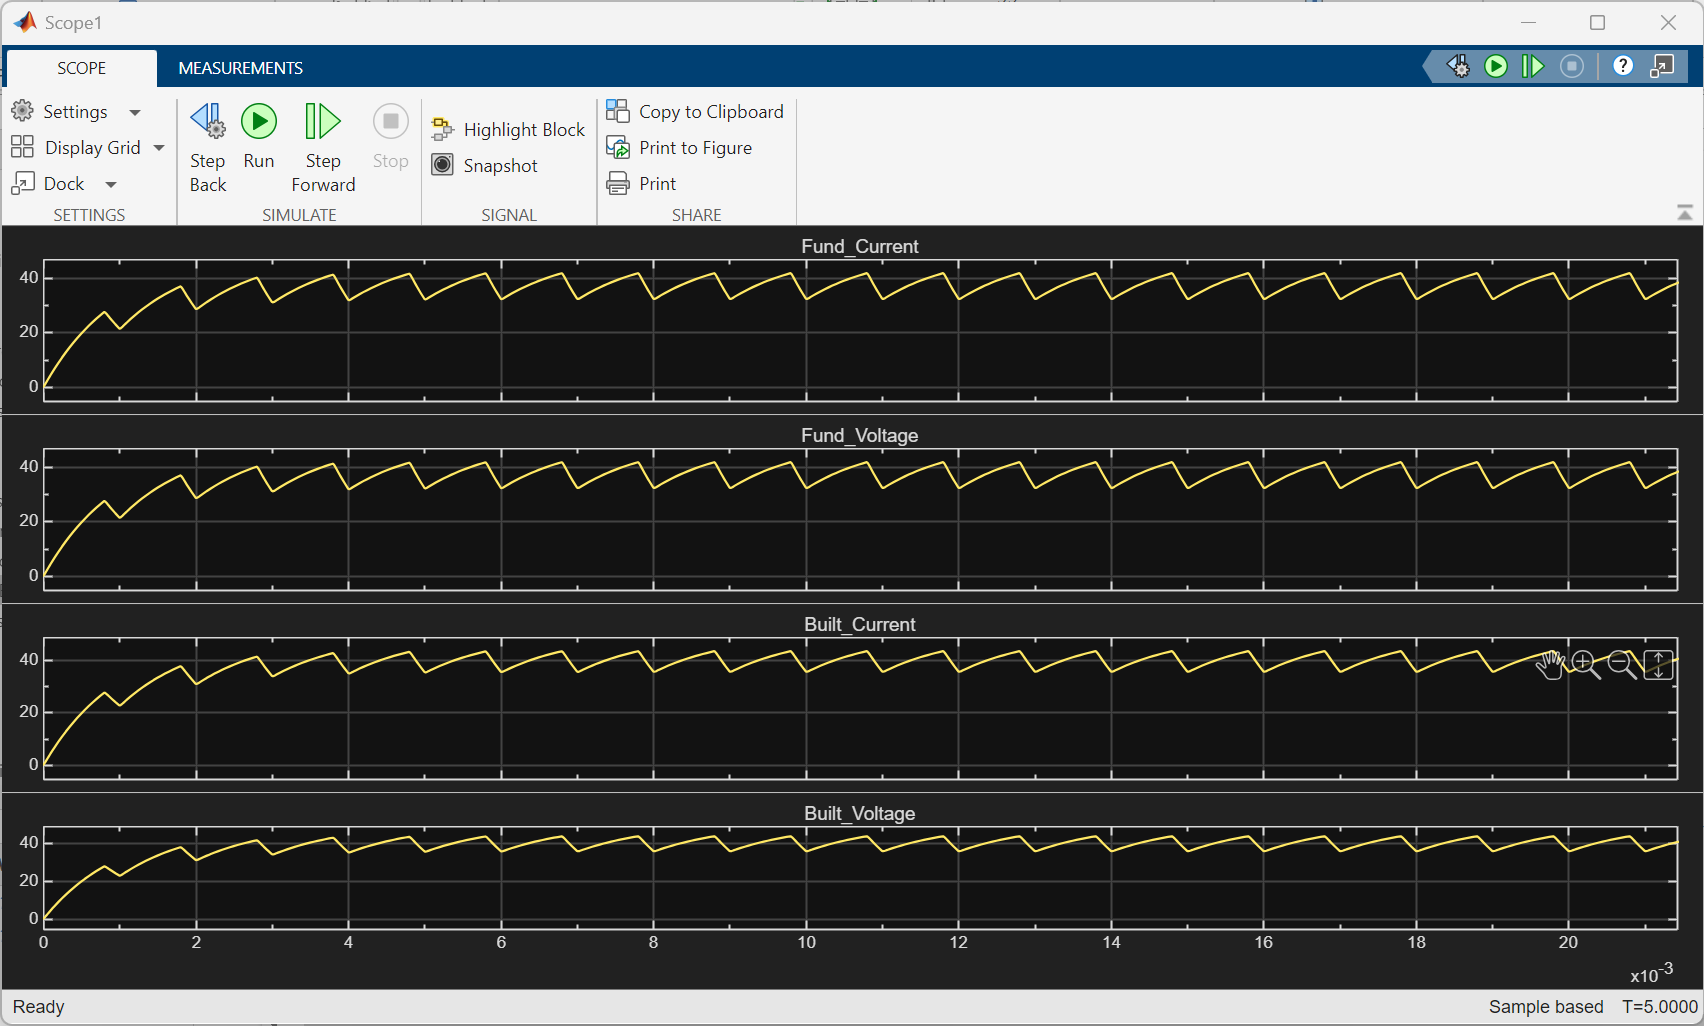

        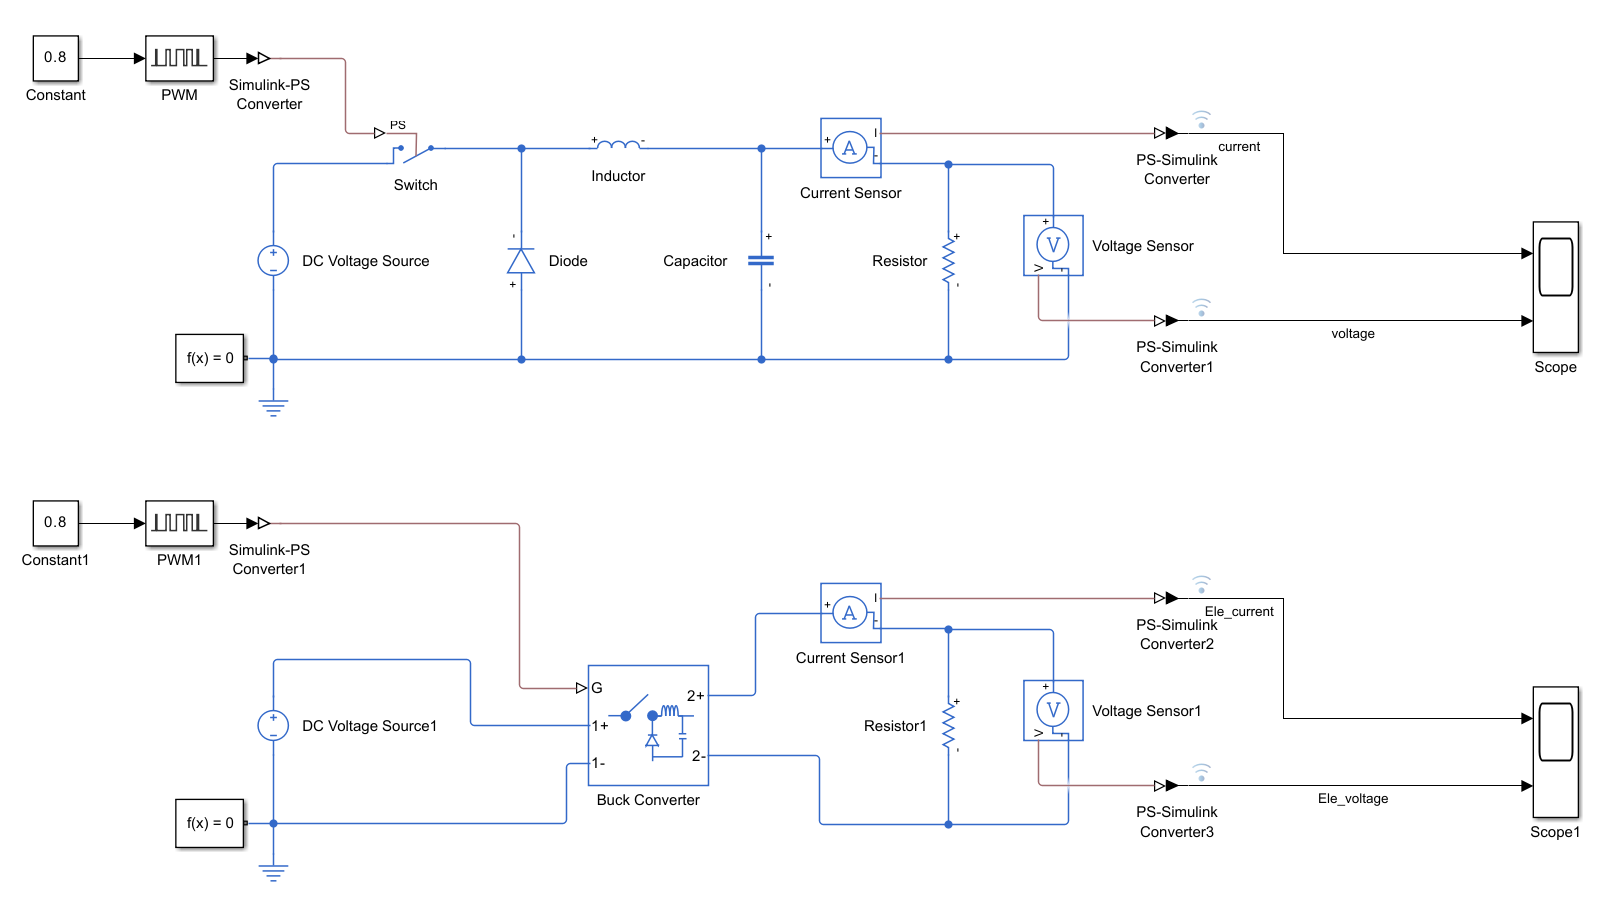

open("Buck_Converter_2_approch.slx")

### Task 3: Achieve higher fidelity model by configuration parameter

- Checking "Buck Converter" Block parameter --> Checking "Switching device" --> Change to "Ideal Semiconductor Switch"

        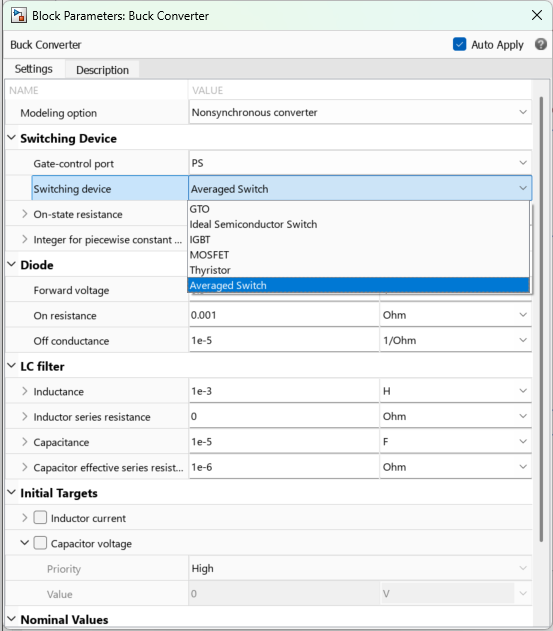

        2. Change simulation stop time to 5 second and click "Run" to start the simulation --> Check the result at "Scope" block compare to the fundamental circuit

        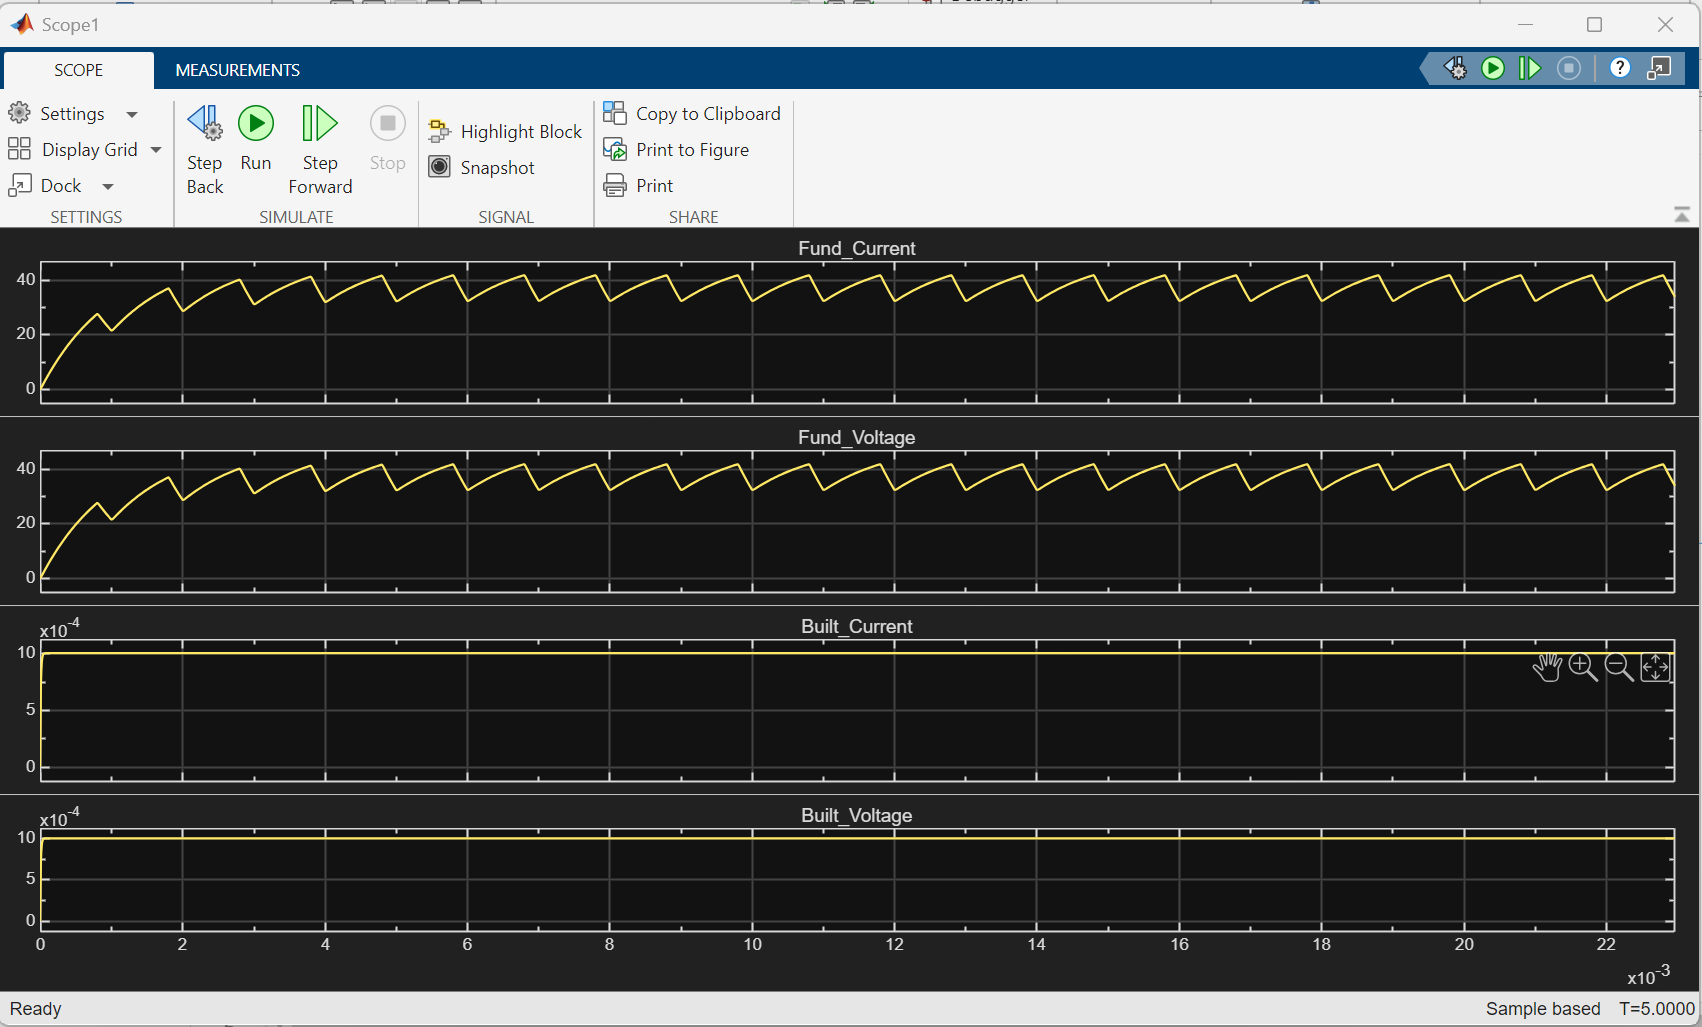

        3. Add "PS Gain" from **Simscape>Foundation Library>Physical Signals **between PWM signal to Gate of "Buck Converter" --> Set the gain at 12

        *PWM voltage signal need to be more than threshold to drive the gate open (More fidelity)

                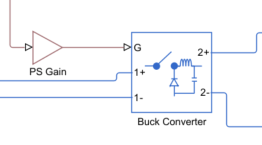

        4. Simulation again and checking the scope

        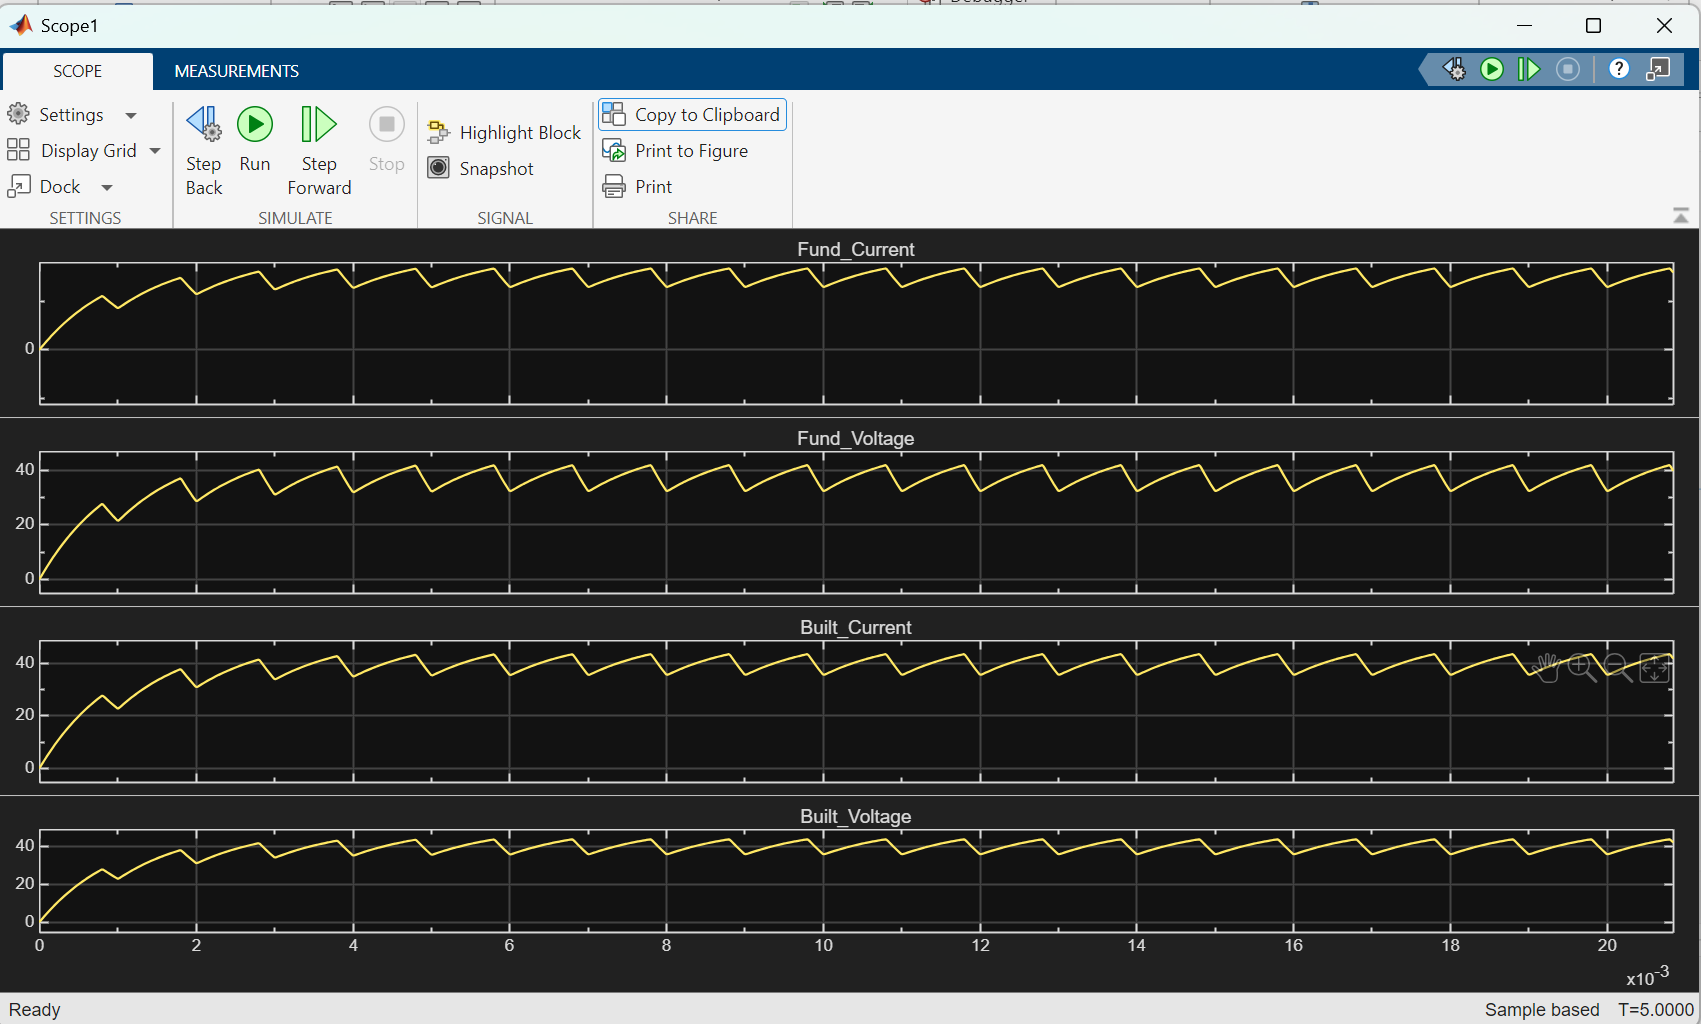

### Task 4: Voltage control with PID controller

- Adding "Unit Delay" block to feedback the Output volage of Buck converter

- Adding "Subtract" block --> Subtract "Feedback voltage" with constant (Set as 40 for the default setpoint) to get the error value

- Adding "PID controller" to make the PID control --> Sending the PWM control to PWM Generator

        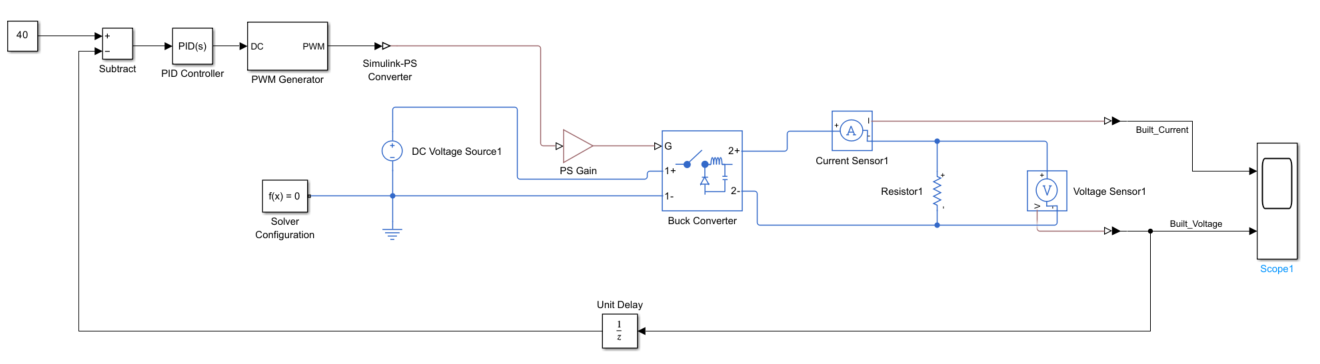

        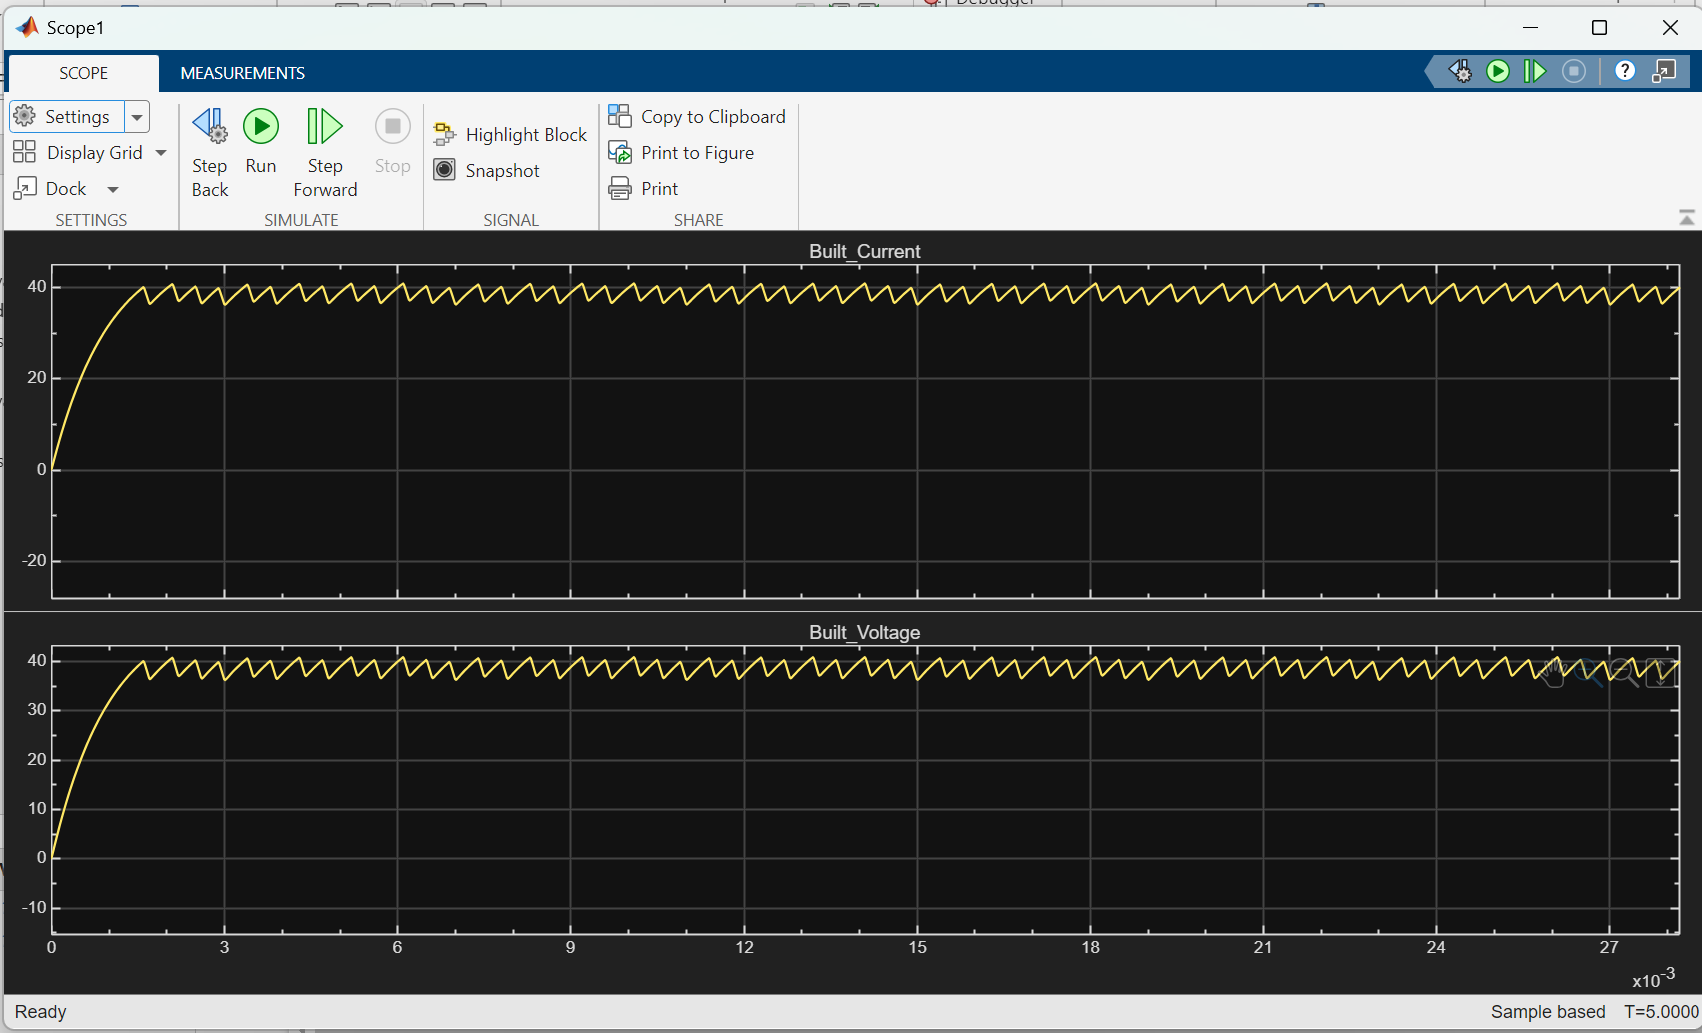

        *You may try to change the value of PID gain by double click at "PID controller" 

        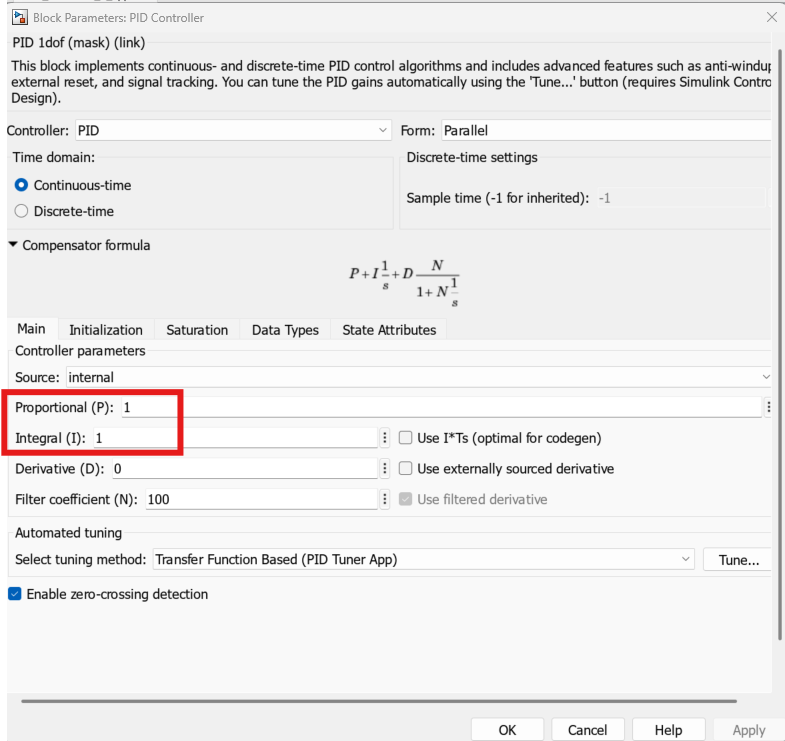

### Task 5: Tunning Controller with PID tunner

- Double click at "**Discrete PID Controller**" --> Click "**Tune**" button

        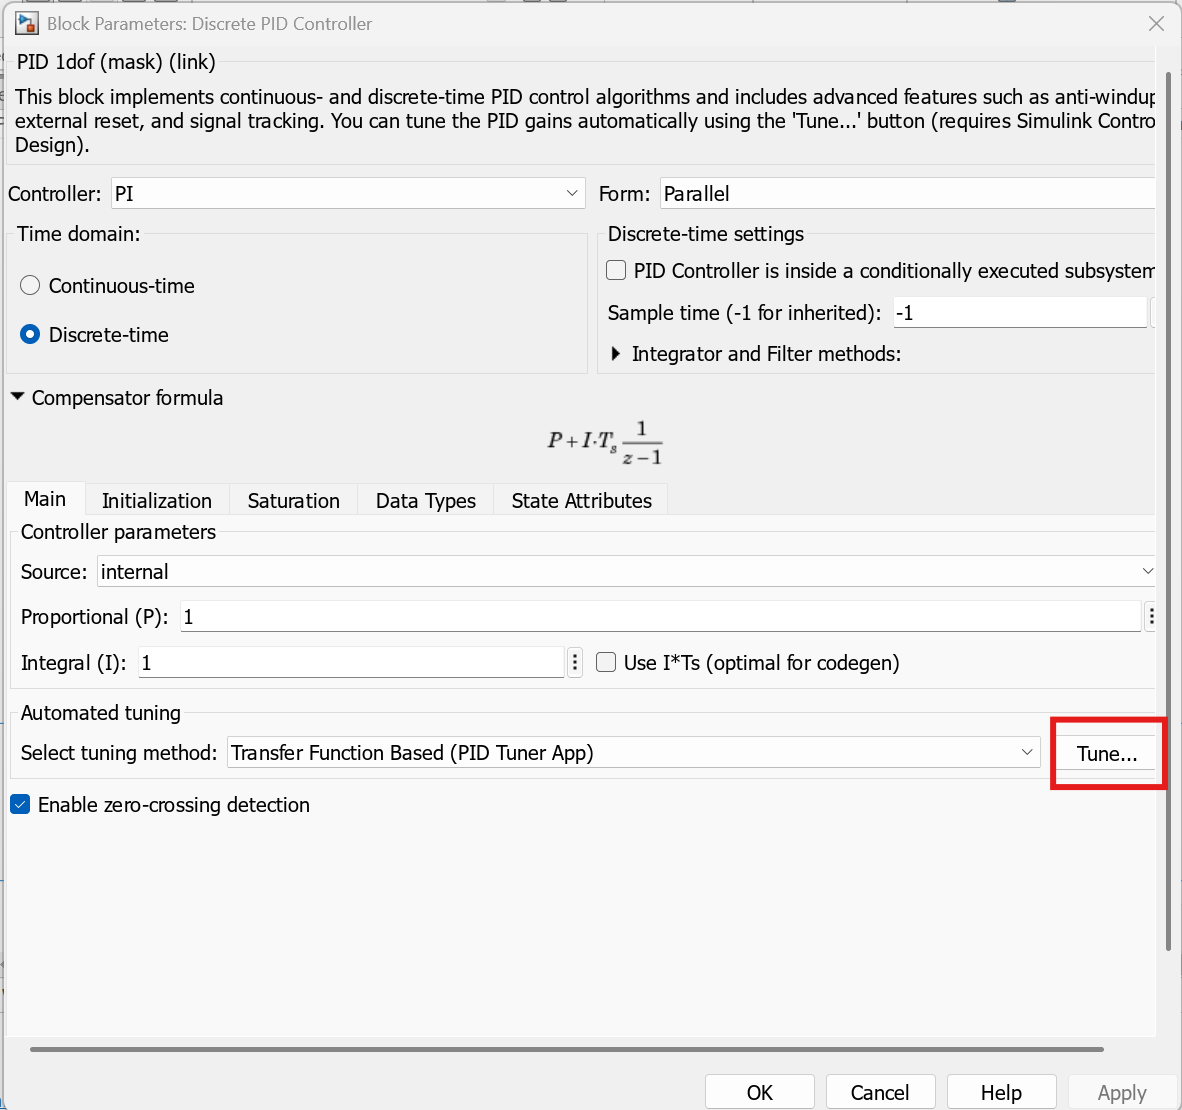

- PID tuner window will pop-up. You can try to tune your controller's "**Response time**" and "**Transient Behavior**" by sliding the bar in picture below --> Click "**Update Block**" after you finished

        *In this case you may face that "Plant cannot be linearized. Use the Plant menu to create or select a new plant." --> Because the system canot be linearized --> Linearize manually     by sellecting the operating point.

        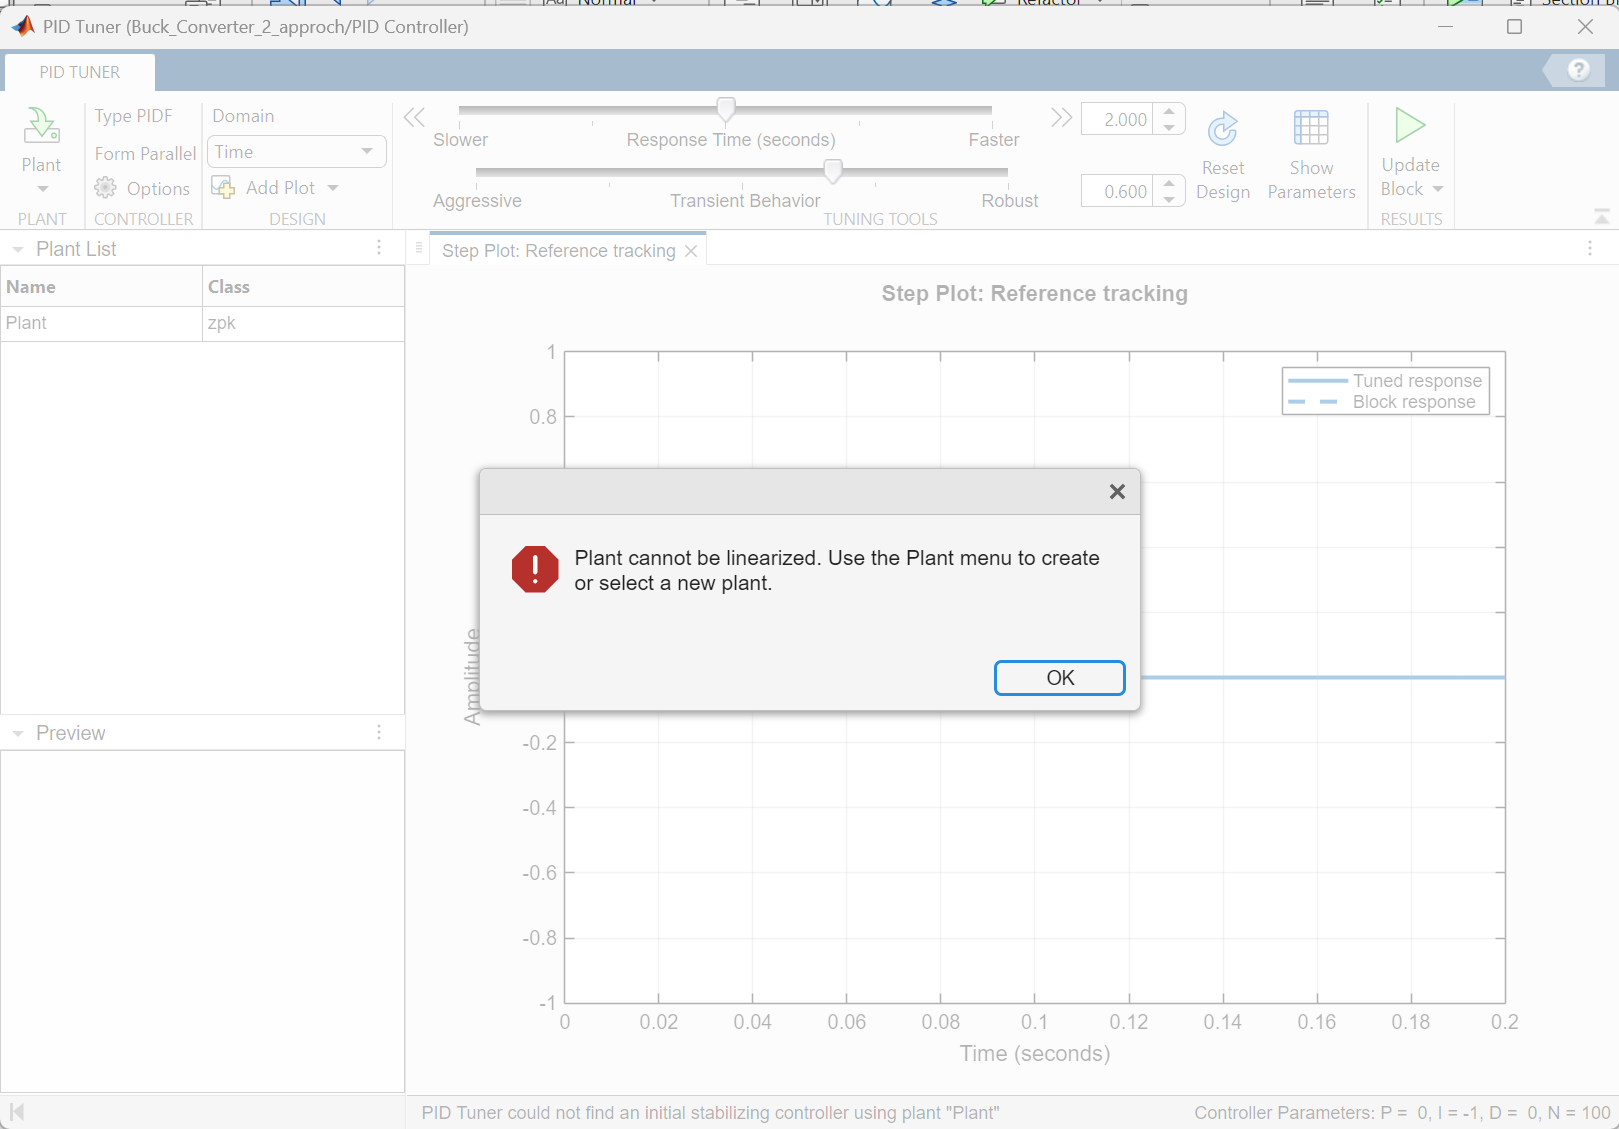

        Goto "Identify New Plant"

        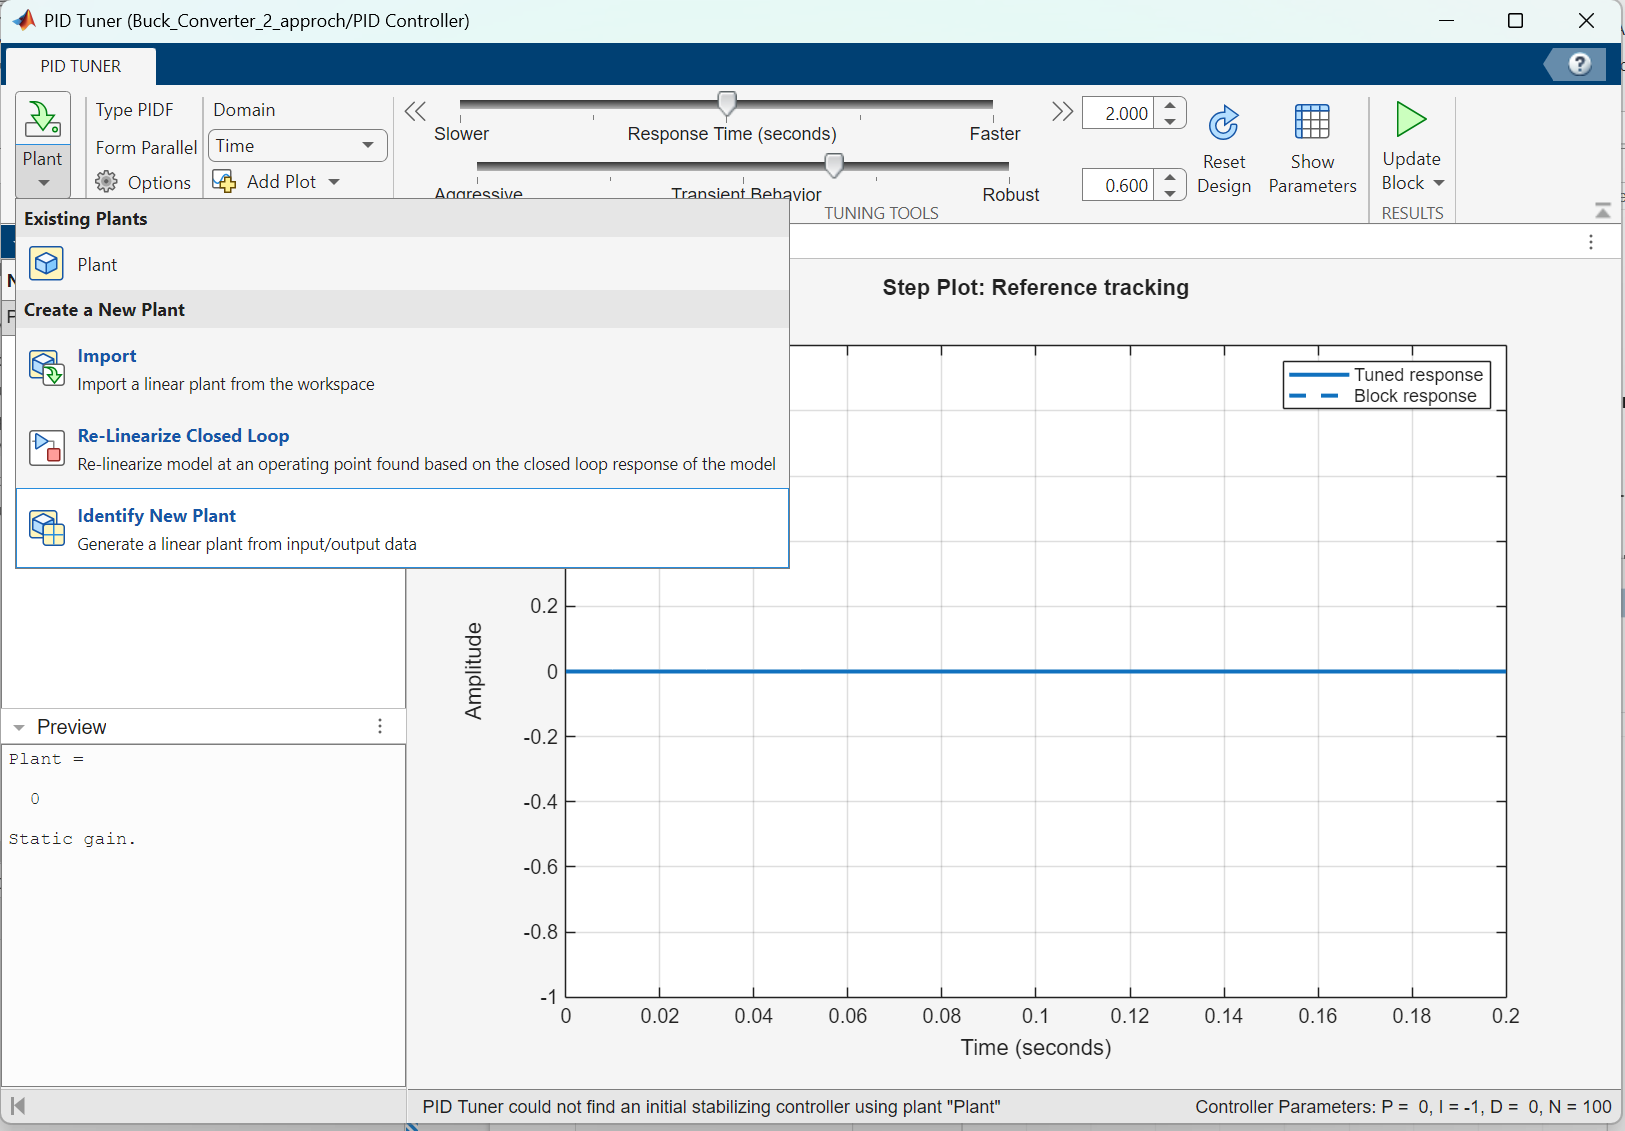

        Go to "PLANT IDENTIFICATION" --> "Get I/O Data" --> Simulate Data

        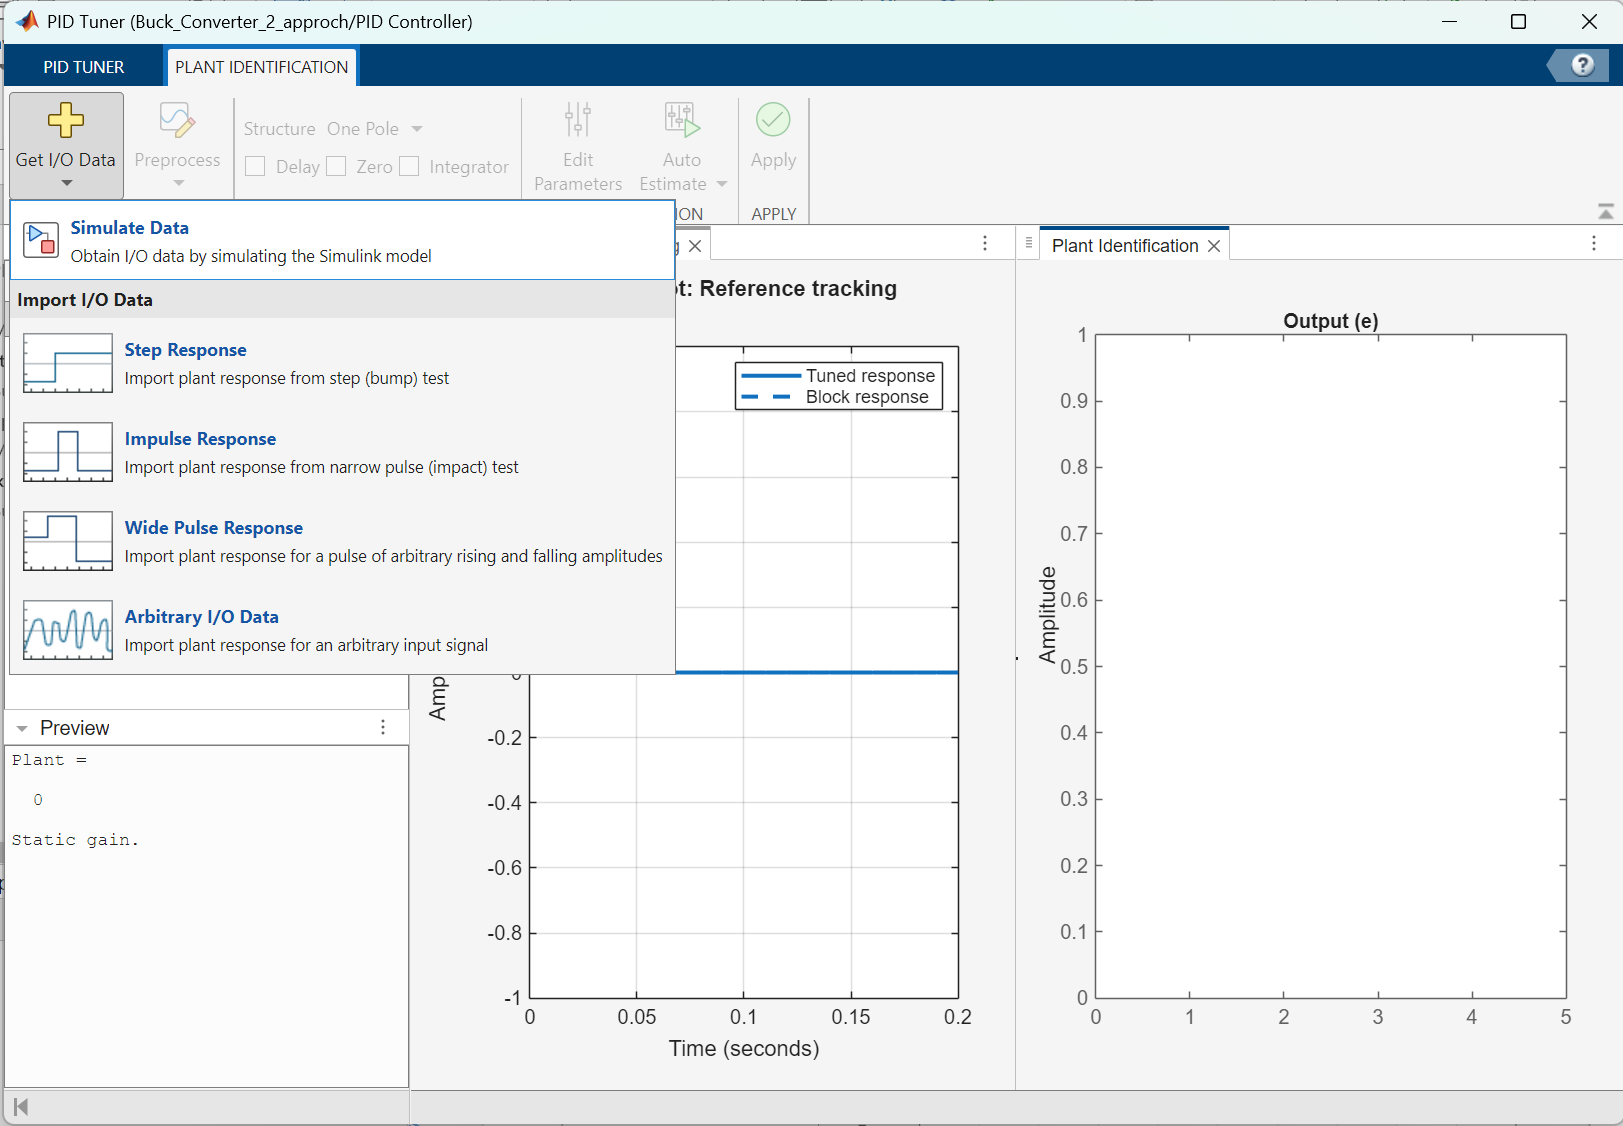

        Identify the model and click "Accept" it

        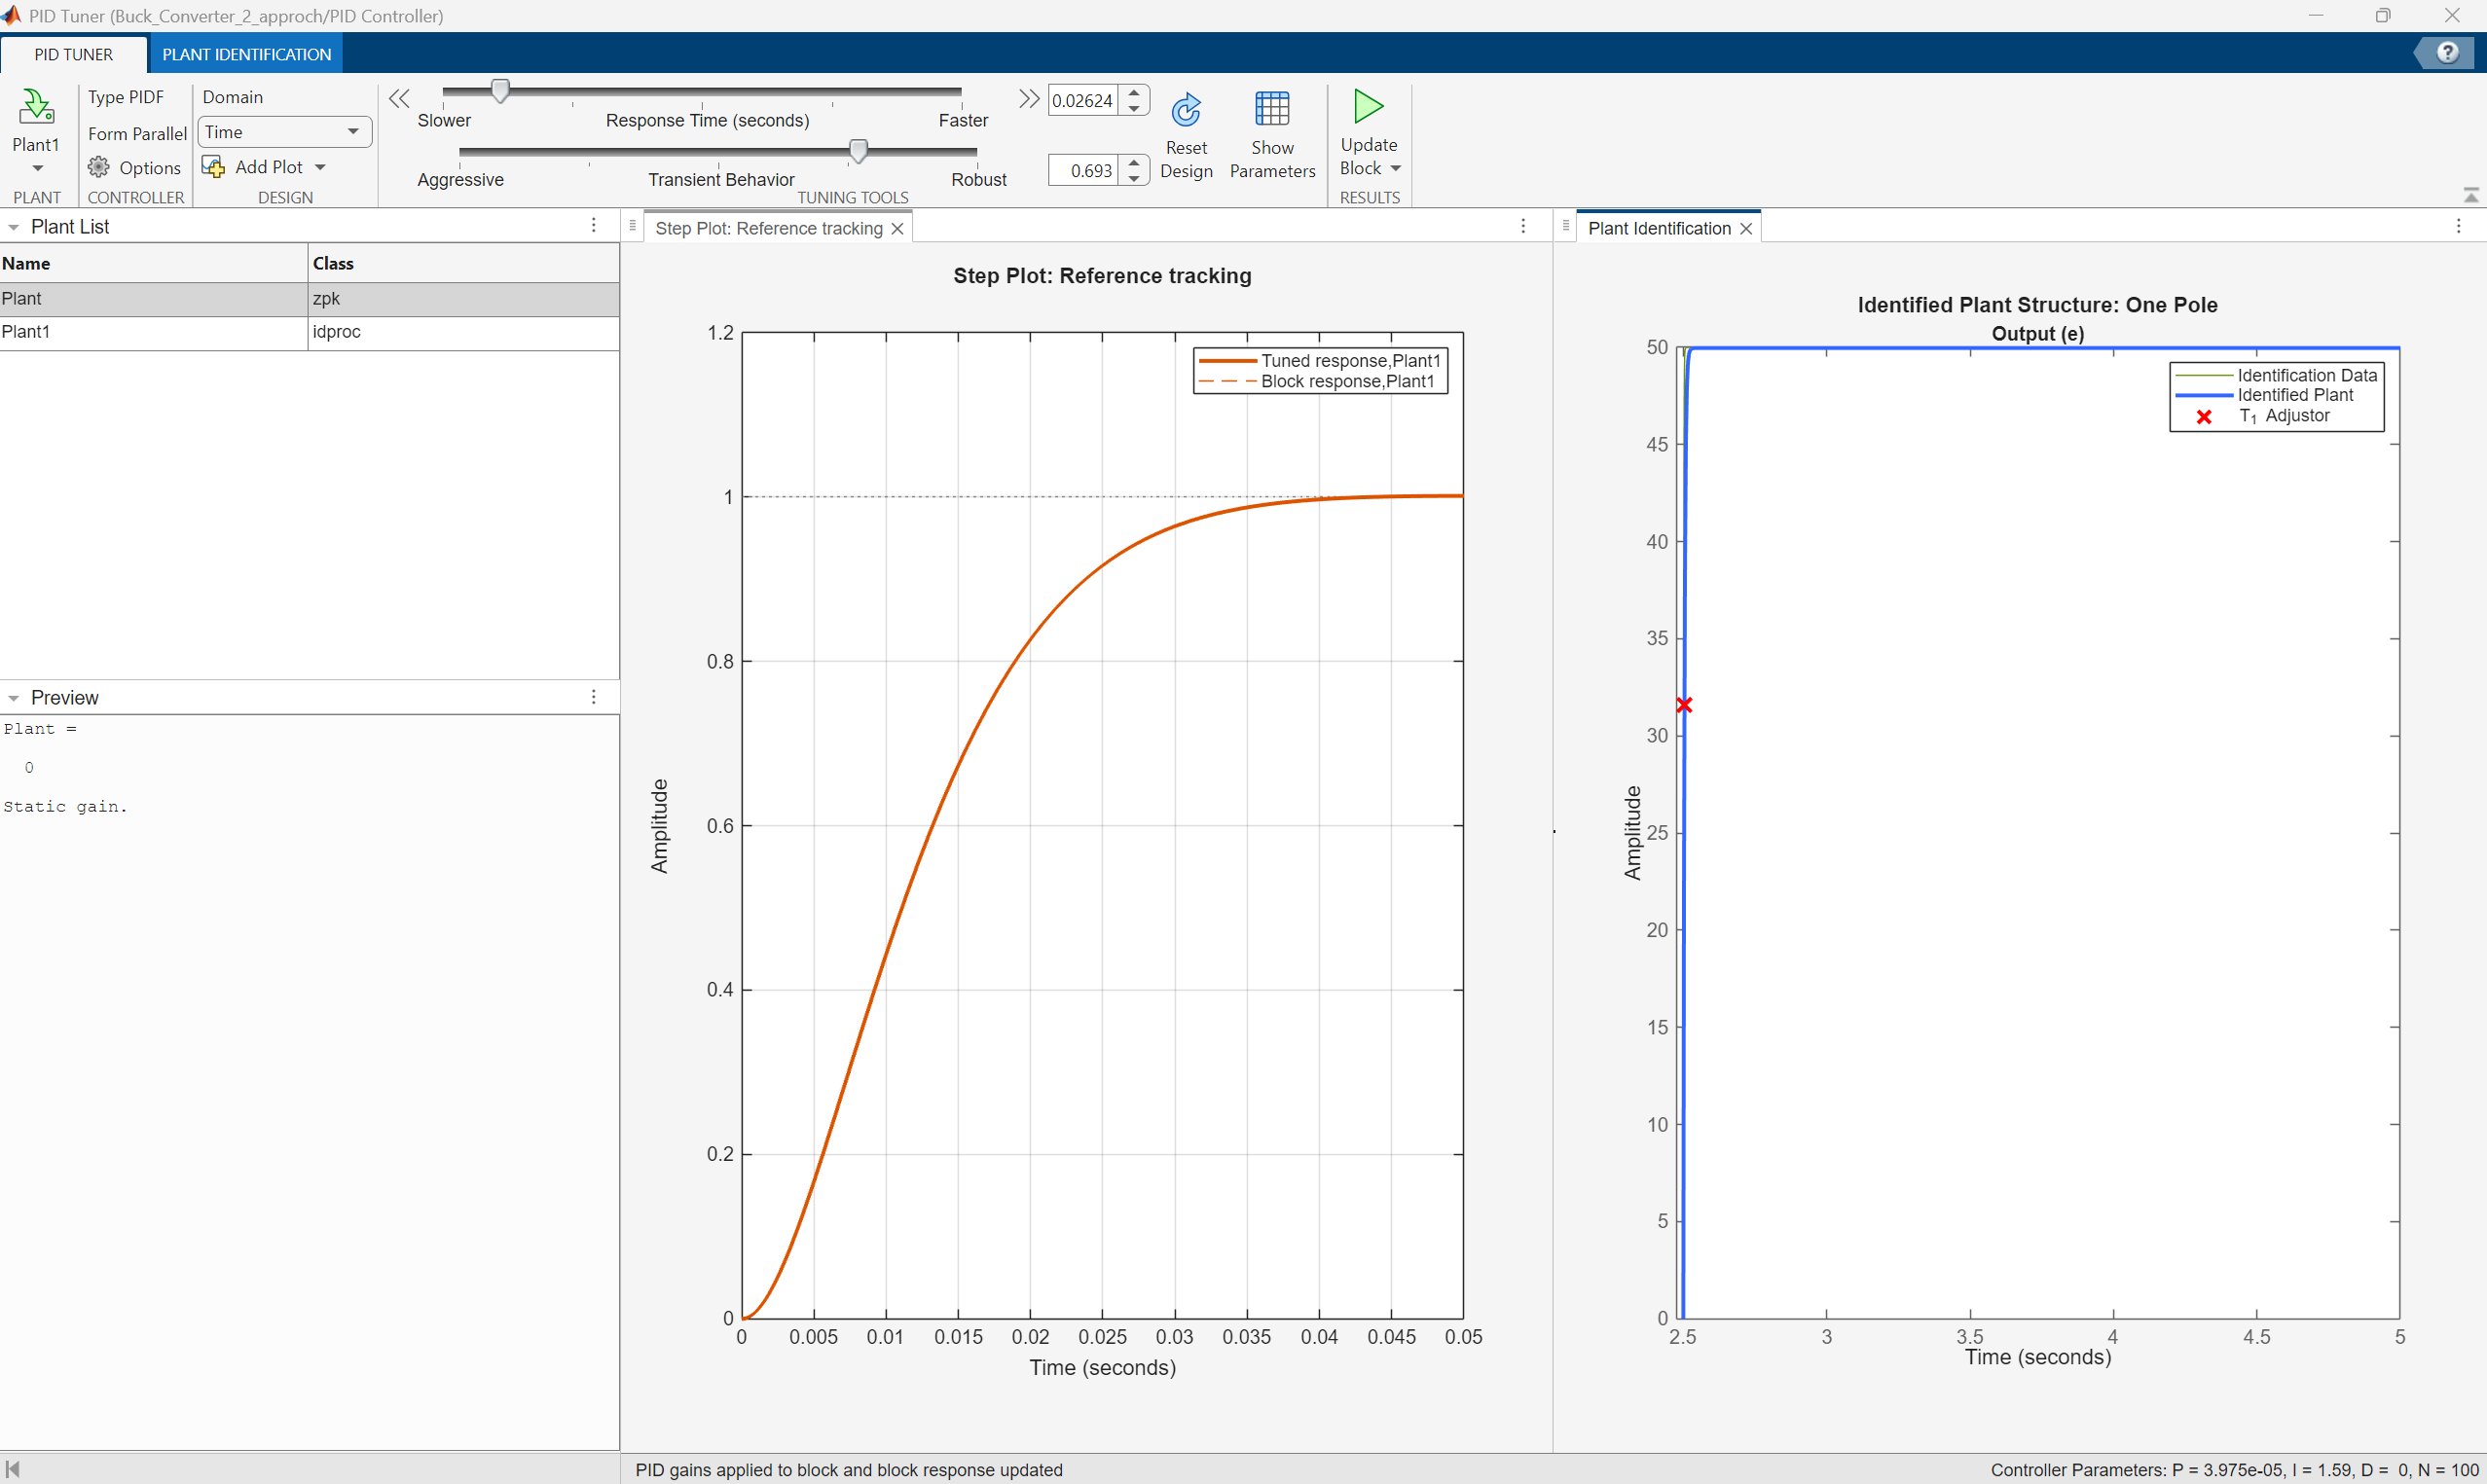

       You can try to tune the response by using sliding bar.

        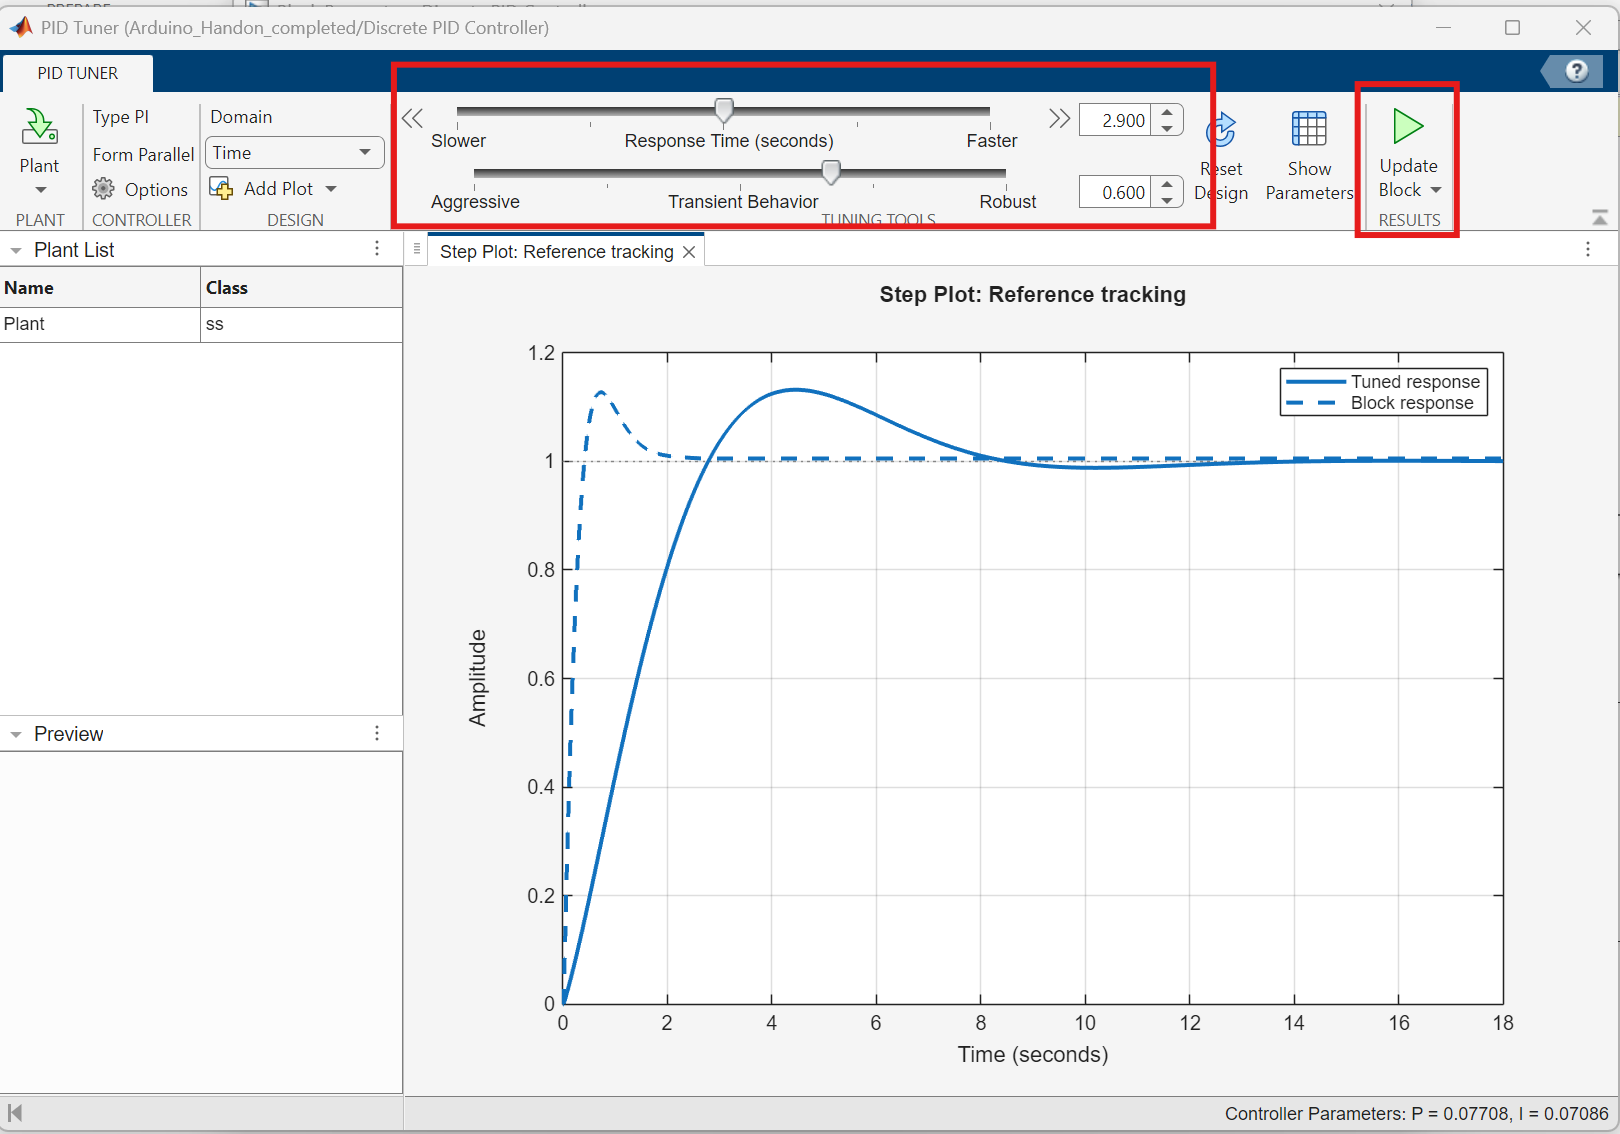

        Try to "**Run**" simulation again to see the chage after you tunning

        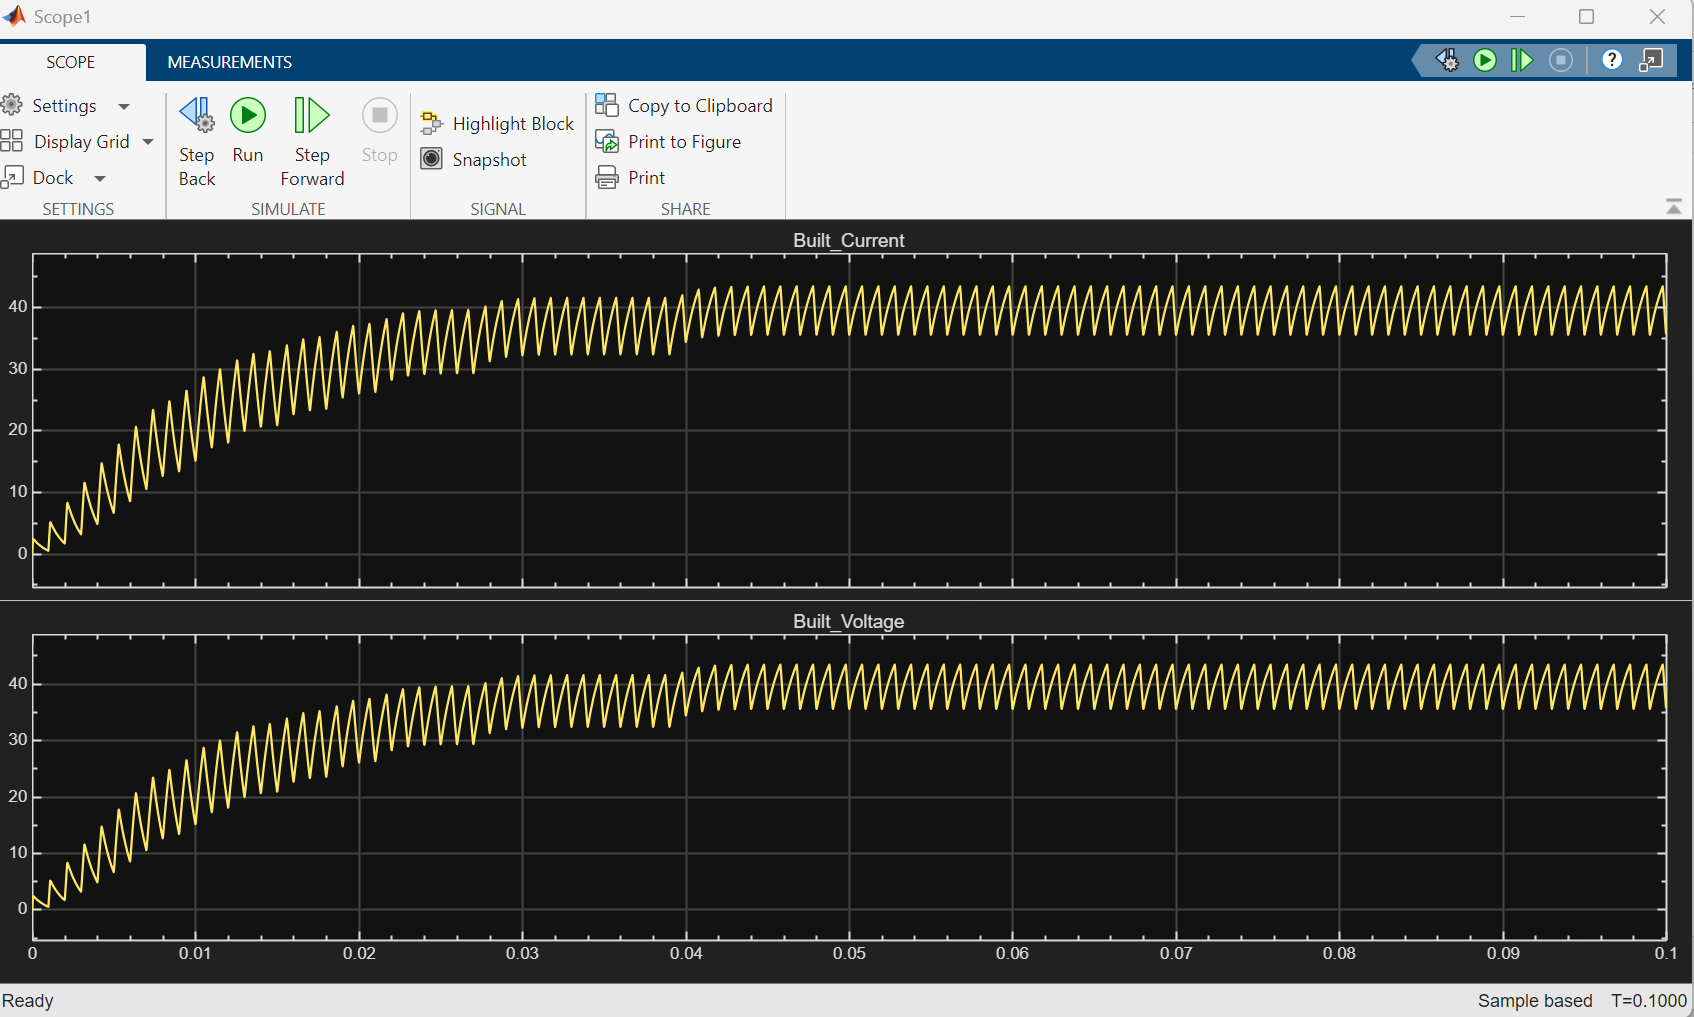

open("Buck_Converter_2_PID_Tune.slx")

## *Optional* Across the Domain (Rotational + Multibody)

### 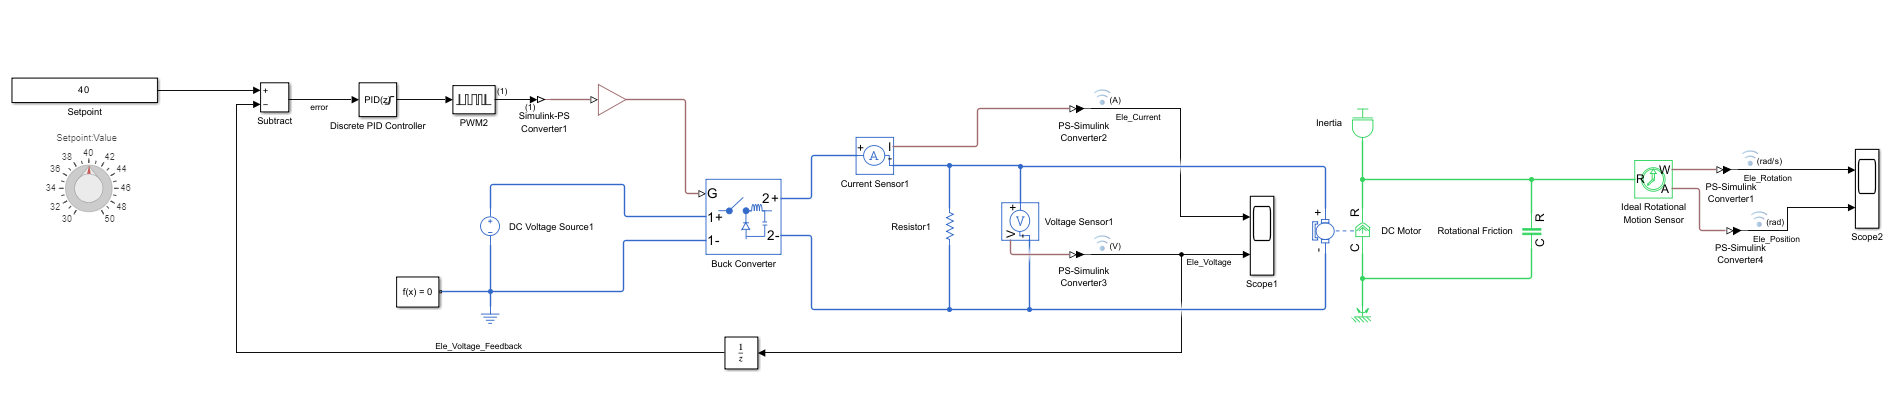

### Task 6: Connect to another domain (Rotational)

- Drag the block from 

            **Simscape>Electrical>Electromechanical>Brushed Motors**

            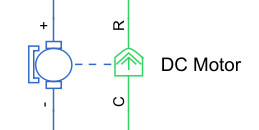

        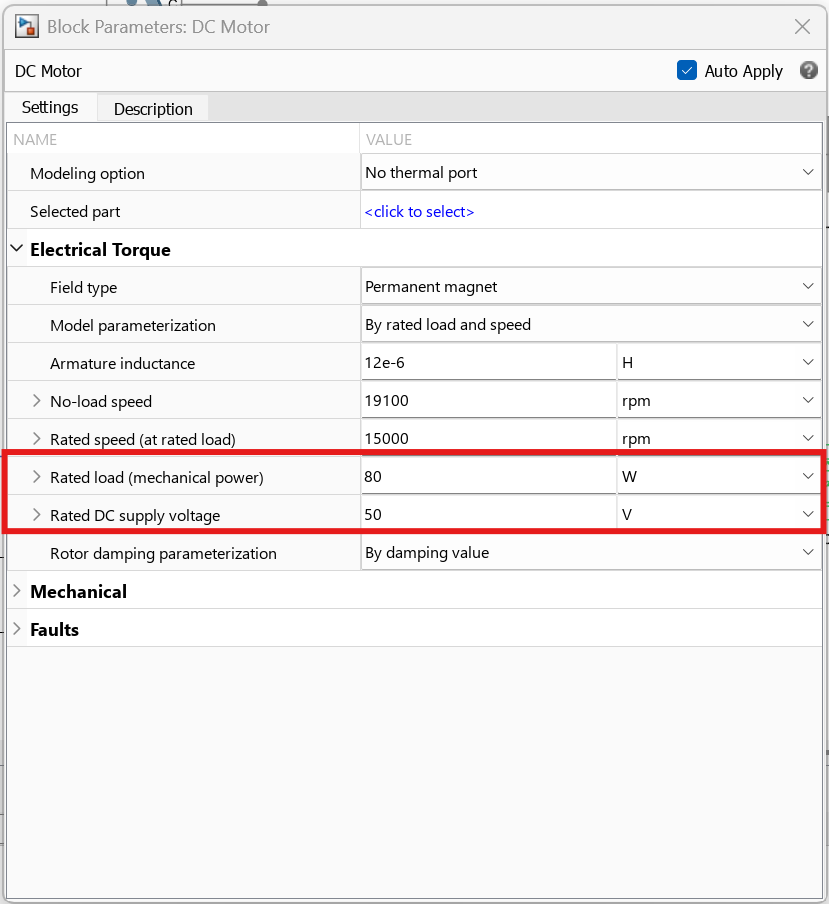

            **Simscape>Foundation Library>Mechanical>Rotational Elements**

            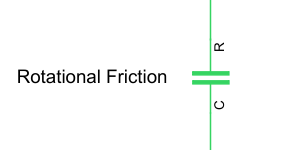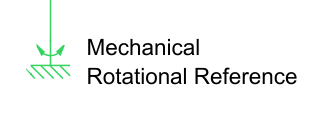

            

            **Simscape>Foundation Library>Electrical Sensor**

            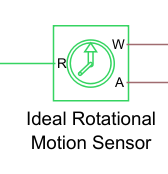

        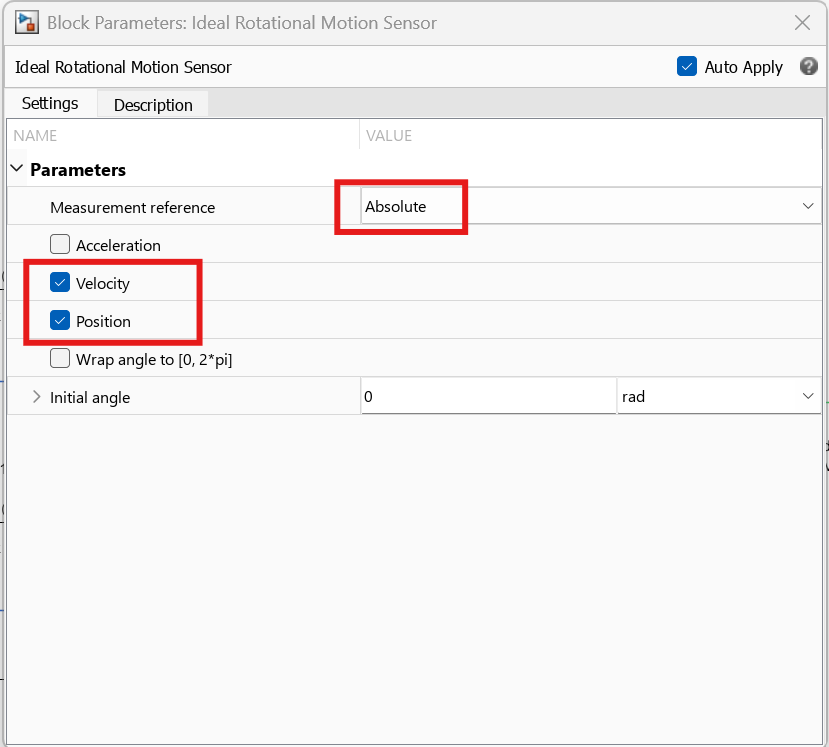

        2. Connect "DC Motor" cascading to the "Buck converter" + Connect the scope to the sensor

        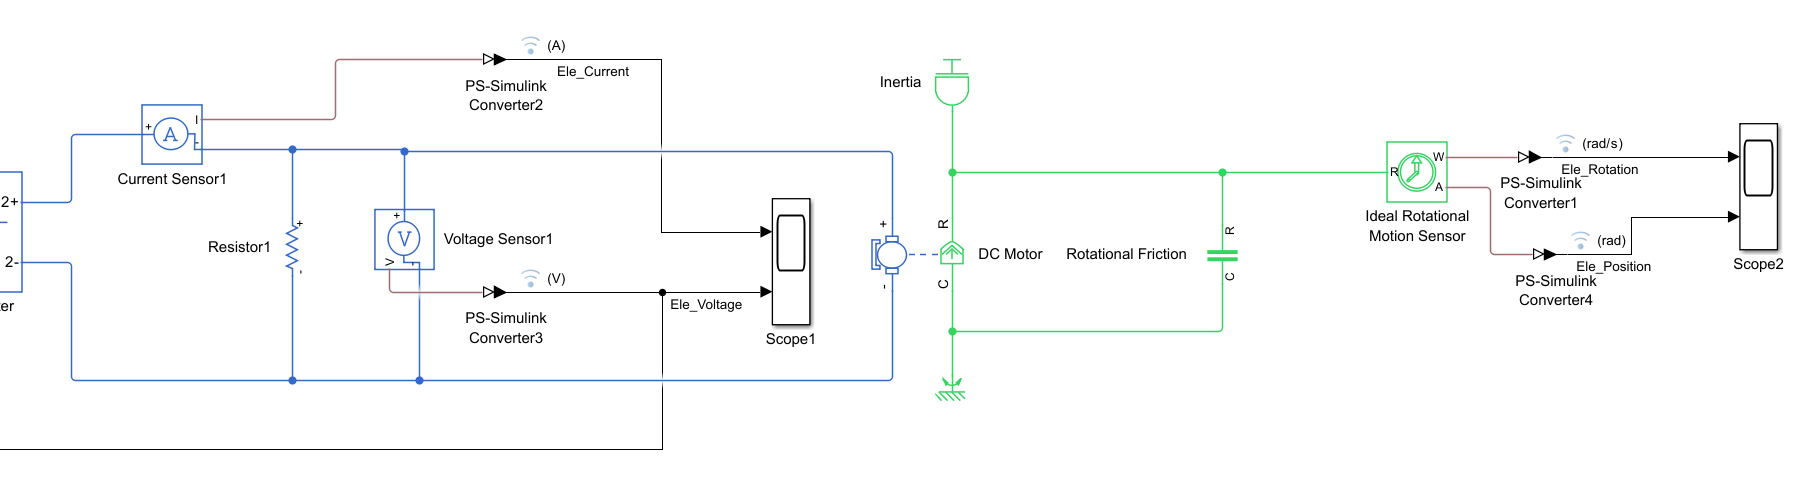

        3.  Simulate at 1 seconds

        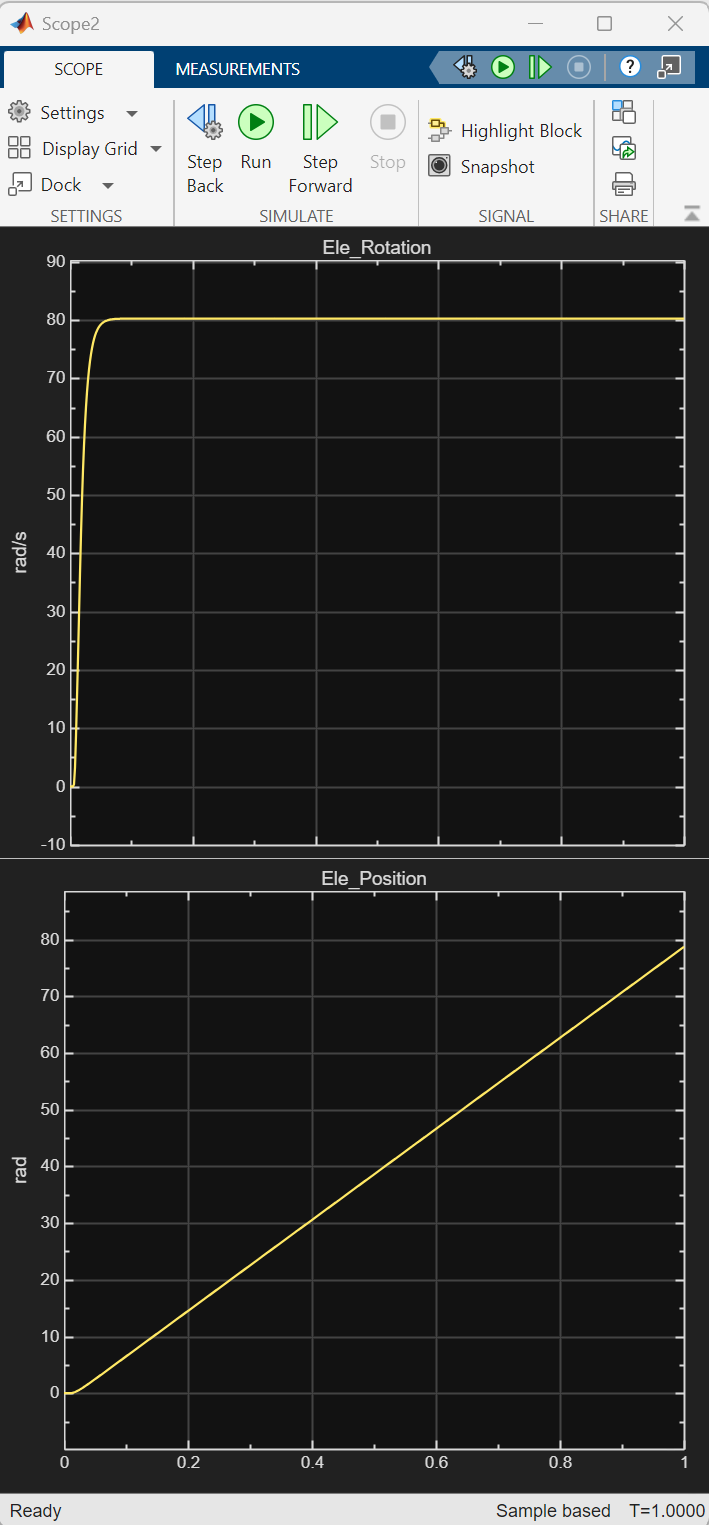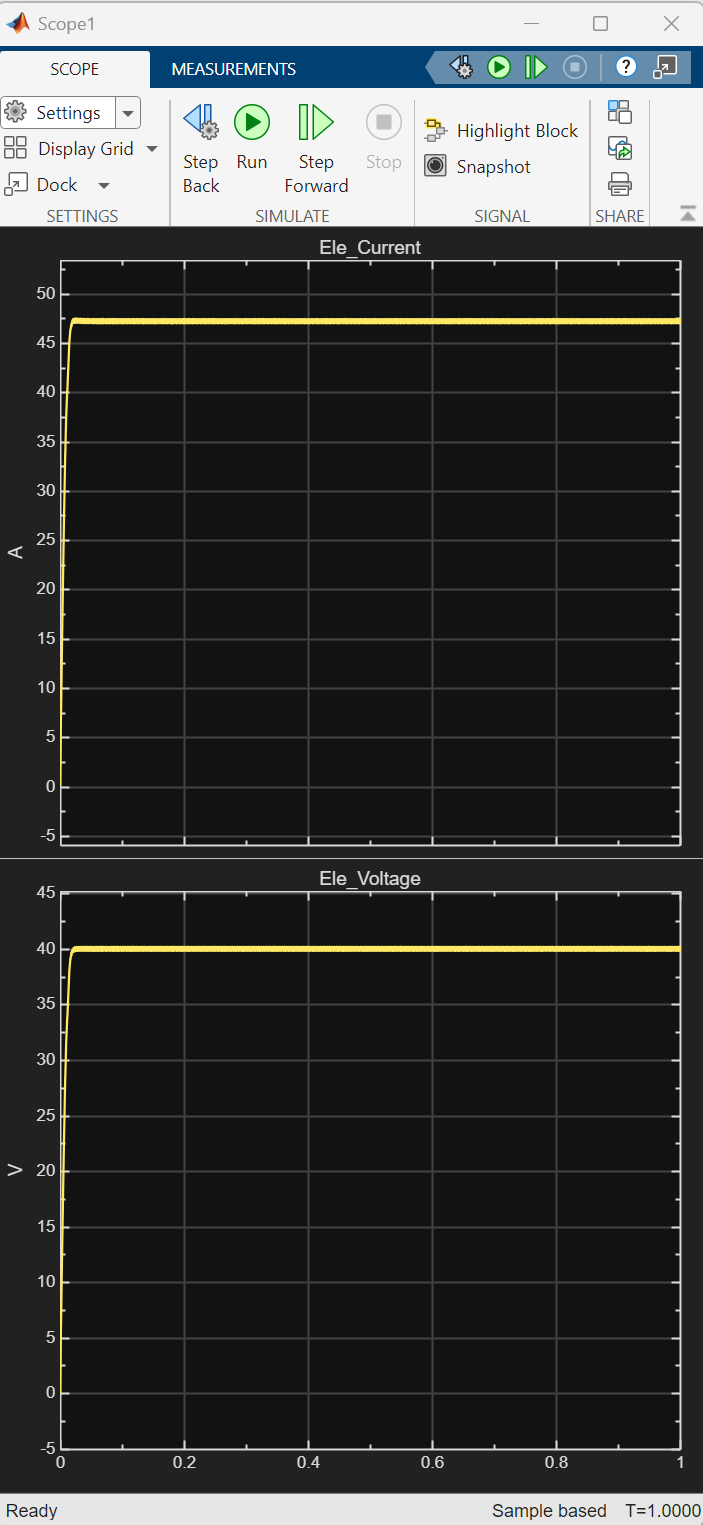

### Task 7: Connect to another domain (Multibody)

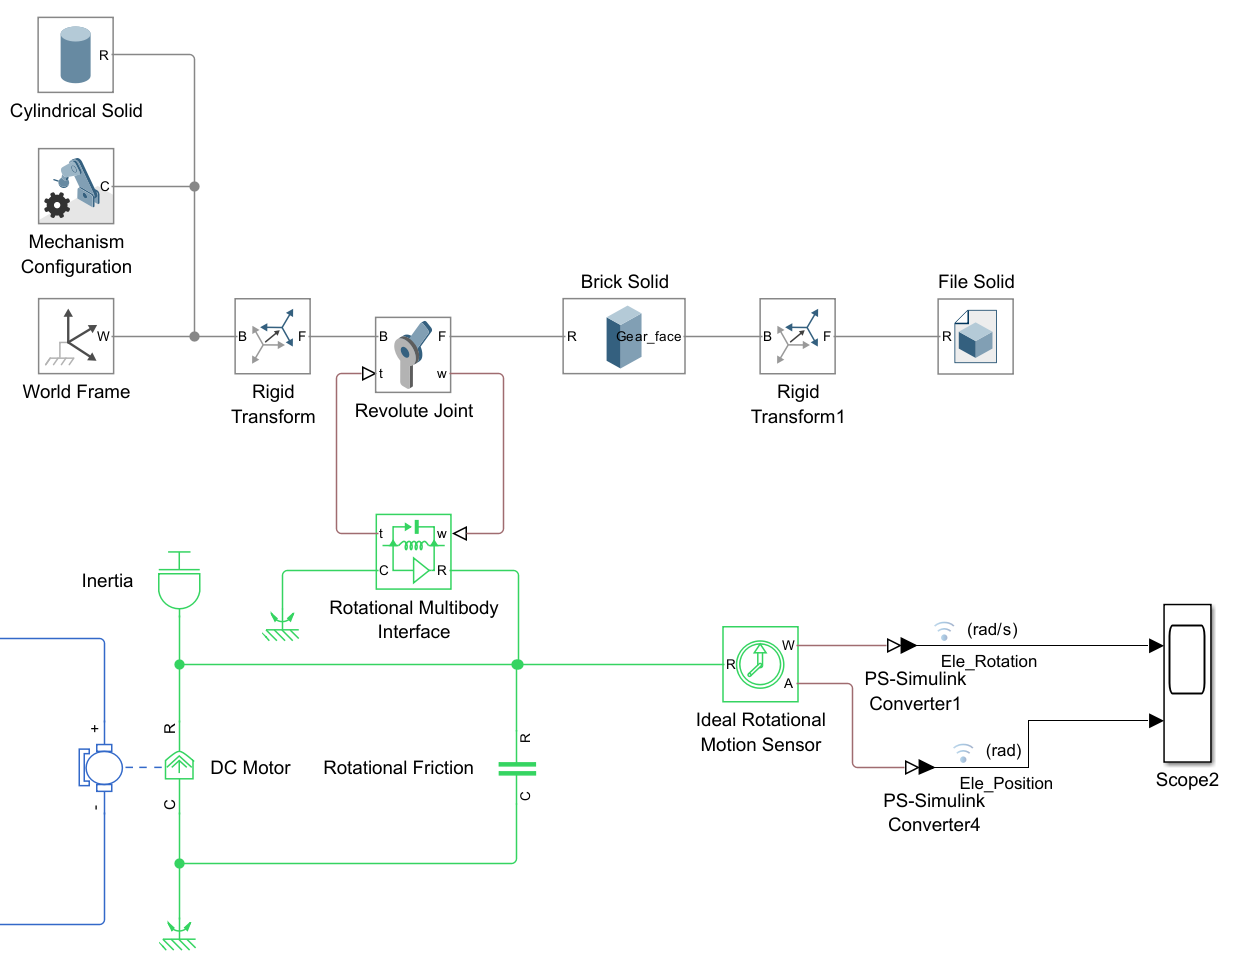

- **[Create Reference] **Drag the block from

            **Simscape>Multibody>Frame and Transforms**

            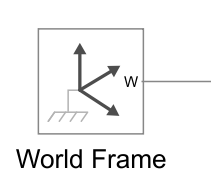

            **Simscape>Multibody>Utilities**

            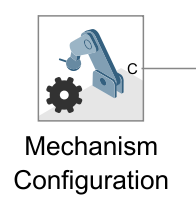

            **Simscape>Multibody>Body Elements**

            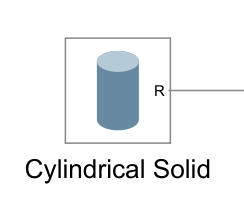

            2. **[Create Joint] **Drag the block

            **Simscape>Multibody>Frame and Transforms**

            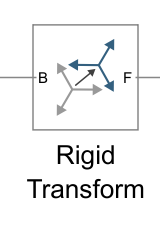

            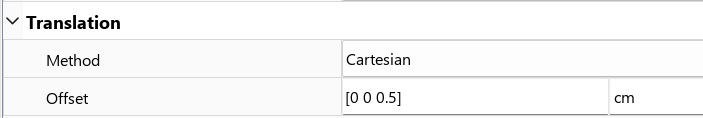

            **Simscape>Multibody>Joints**

            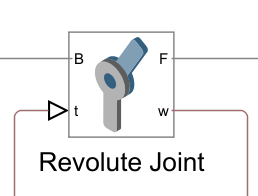

            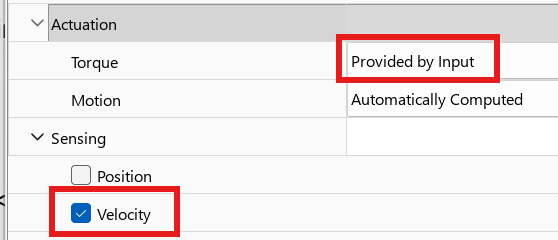

            **Simscape>Multibody>Body Elements**

            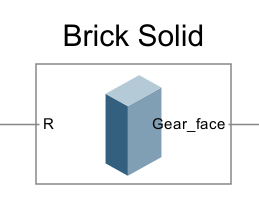

            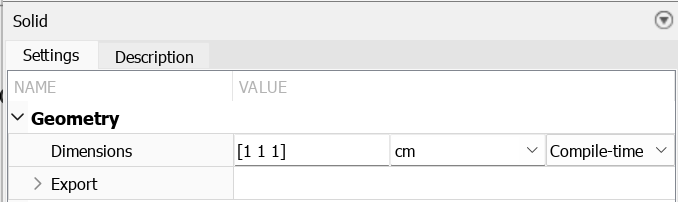 

            **Simscape>Simscape Mechanical Interfaces**

            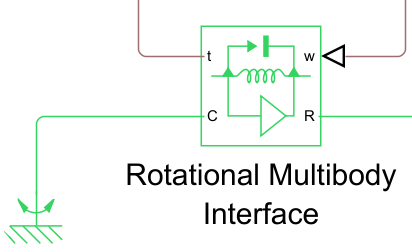

            3. Connect model together

            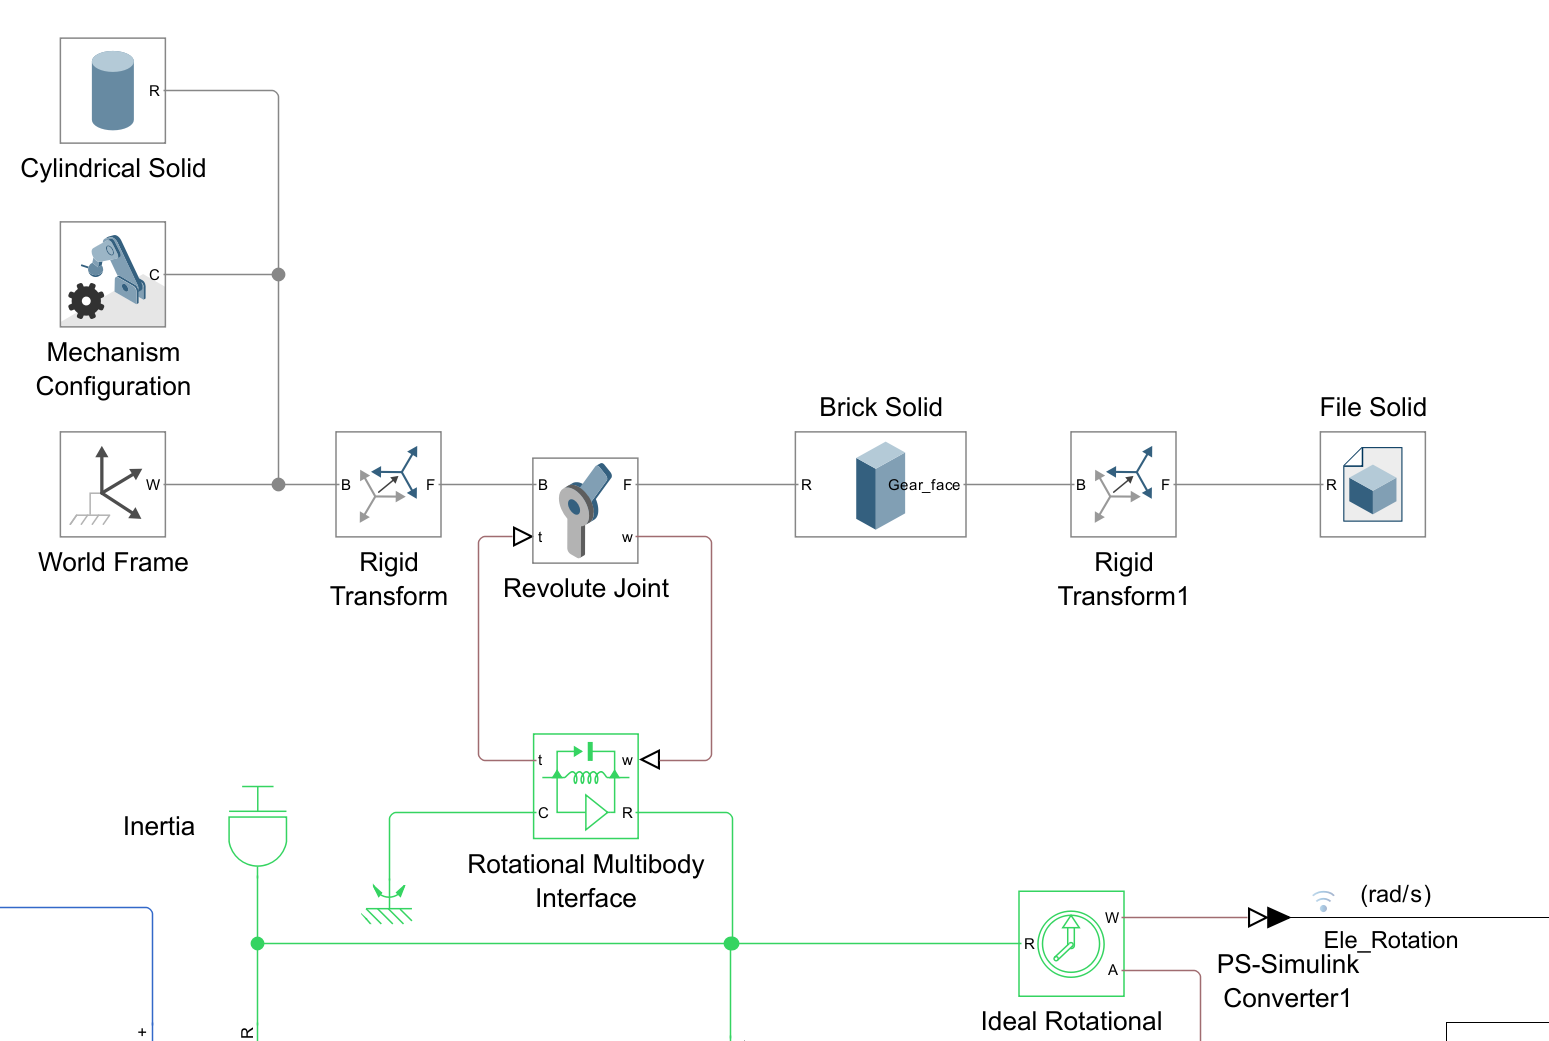

            4. Simulate at 1 seconds